# **Learning regions of attraction from data**

    In this work, we want to find a piece-wise affine Lyapunov function $V$ for a known equilibrium point of our system with a smaller attraction set $A$, in an extended set $X$ excluding $A$ ($X\setminus A$), based only on a dataset of said system and information on the bounds of the function (Lipschitz constant). For the function to be piece-wise affine, the set $X\setminus A$ is partitionned according to an $N_c$-tessellation $\{Y_c\}\underset{c=1,...,N_c}$ such that :


$$\overline{X\setminus A} = \bigcup_{c=1}^{N_c} Y_c$$



$$c\neq c' \Longrightarrow \mathrm{int}(Y_c)\cap\mathrm{int}(Y_{c'}) = \O$$


The function would then have the following expression :


$$\forall x \in Y_c \subset X\setminus A \ , \quad V(x) = g_c^\top x+b_c \quad \quad 1 \leq c \leq N_c$$


To do so, we follow these steps :

- build a tessellation of the set $\overline{X\setminus A}$ ;

- generate a dataset $\{(x_d,f_d)\}_{d=1,...,N_d}$ that is informative on our tessellation ;

- solve the optimisation problem ;

- check if the result is indeed a Lyapunov function.

clear all

**Step 1 :** generating the tessellation.

For this, we will consider $X$ and $A$ to be rectangles (or squares) for which we provide the limits l and l_A. Next, we fix the desired number of vertices Nv of the tessellation. Last, we select the tessellation type : either with random vertices or with regularly distributed ones.

**N.B :** the 'random' tessellation doesn't change Nv, but the 'regular' one can only take specific values so Nv is rounded to the closest value to the original desired number.

l = [-1,1;-1,1]; % 0.75*[-1,1;-.5*sin(1),.5*sin(1)];
Nv = 160;
l_A = .1*l;
tesstype = 'regular';
[C,v,dA,dX,Nv,Nc,Tess] = TessellationGenerator(l,Nv,l_A,tesstype);

We plot the resulting tessellation.

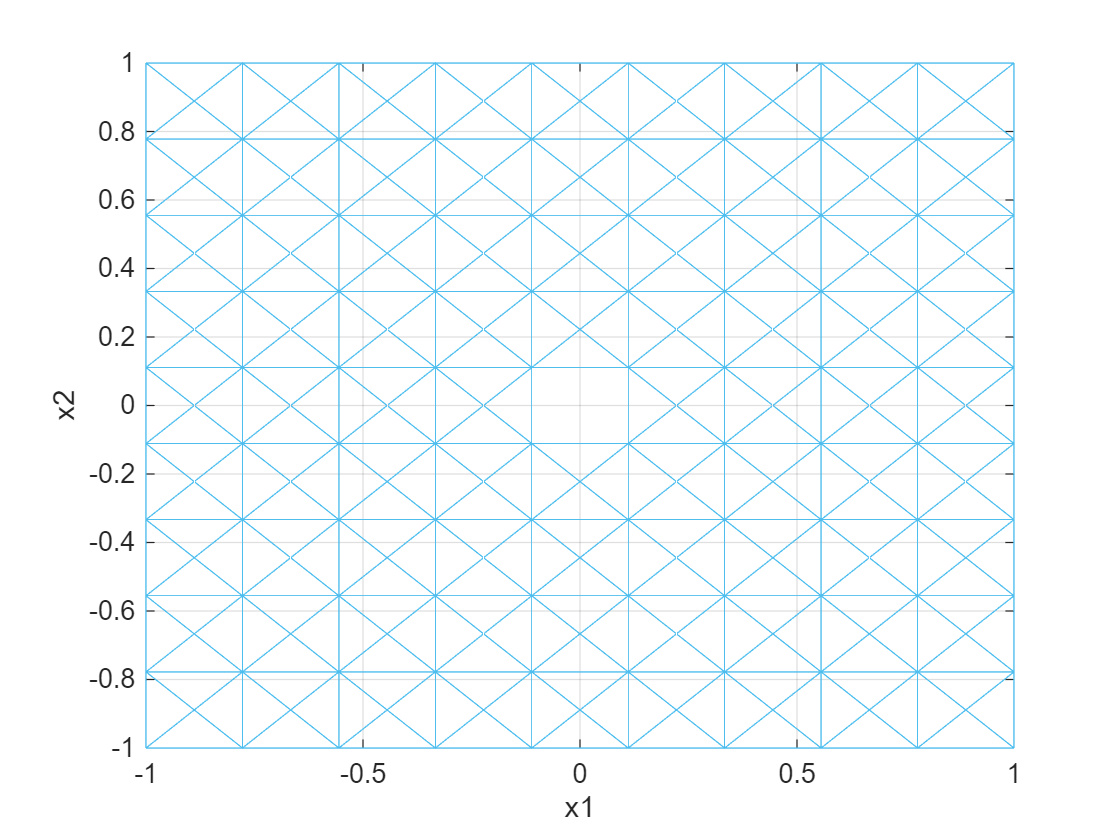

figure
triplot(C, v(1,:), v(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

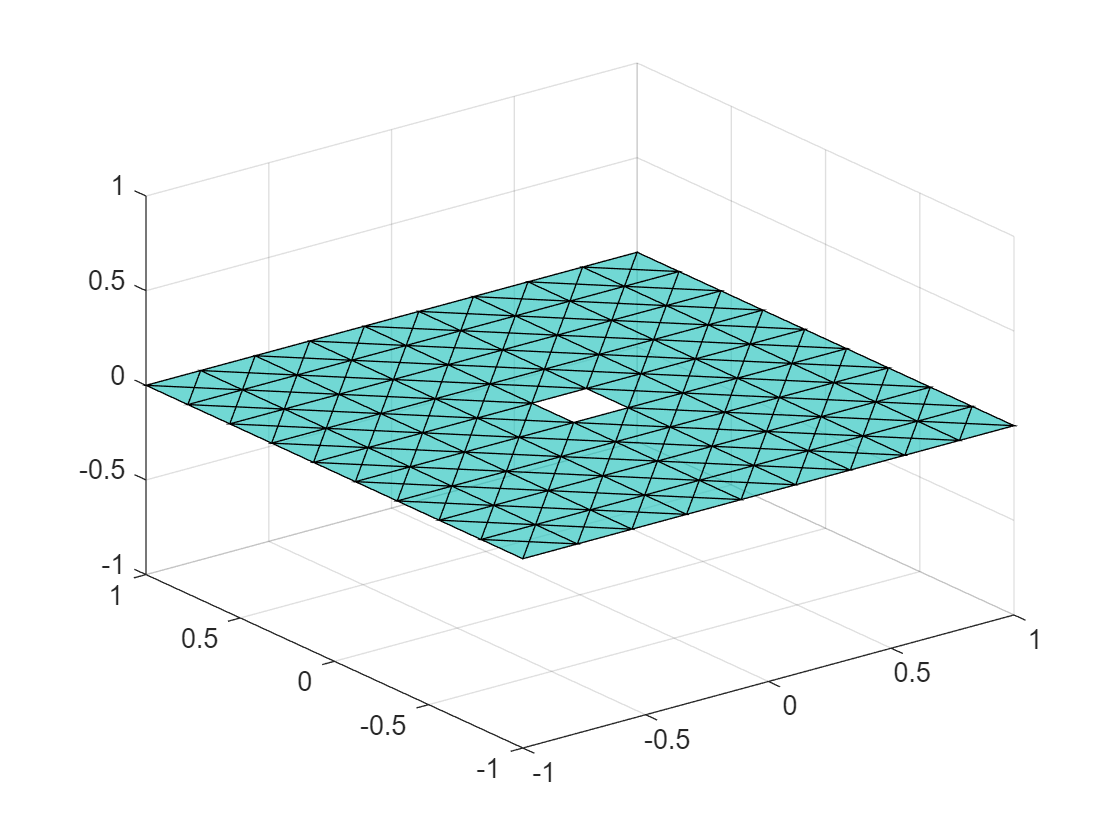

figure
trisurf(C,v(1,:),v(2,:),zeros(length(v),1),'FaceAlpha',.6)
grid on;

**Step 2 :** generating data.

In this part, we fix the number Nd of datapoints generated initially. The potential dataset is tested to see if it is informative with respect to the tessellation. If it is not, the dataset is regenerated. After a certain number of regenerations and failed tests, the number of datapoints is increased. This goes on until we get a valid dataset, which will then be cleaned of uninformative datapoints.

Nd = 300;
sample_ratio = 1.1;
system = 0;
nrm = 2;
M = LC(system,nrm);
dtype = 1;
[x,f,Nd] = DataGenerator(Nd,sample_ratio,l,v,Tess,system,M,nrm,dtype);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

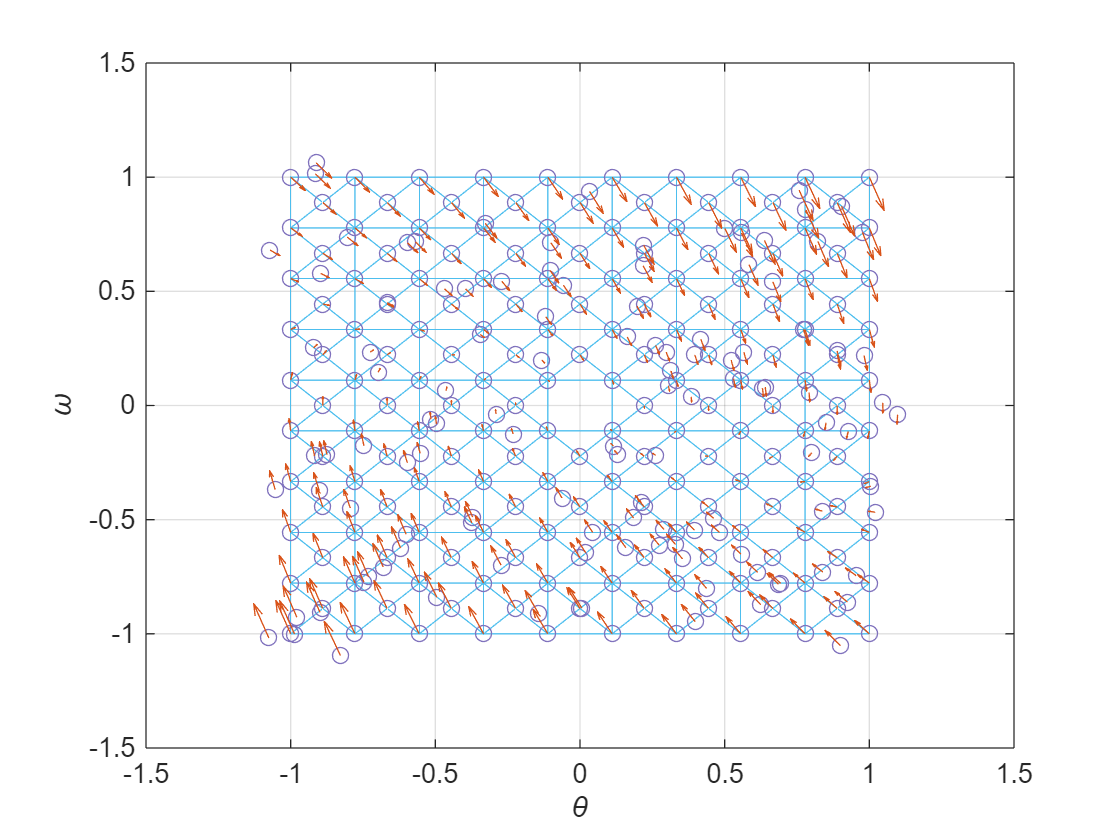

figure
triplot(C, v(1,:), v(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x(1,:), x(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x(1,:), x(2,:), f(1,:), f(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

**Step 3 :** optimisation problem.

In this part, we try to find the piecewise affine Lyapunov function $V$ as described in the introduction through an optimisation problem.

eps = 1e-2; % negativity tolerance
eta = 5; % slack margin
upperlim = 200; % upper limit of the Lyapunov function
lowerlim = 0; % lower limit of the Lyapunov function
lim_mode = 0; % additional constraints on function edges wcn
clear gs bs vals ss sum_ss
[gs,bs,vals,ss,sum_ss] = OptimisationProblem(x,f,M,v,C,eps,eta,upperlim,lowerlim,dA,dX,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 320
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 1.3473e+03
       solvertime: 28.8841
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 1426.028129 seconds.
optimization ended
 


We plot the solution in 3D.

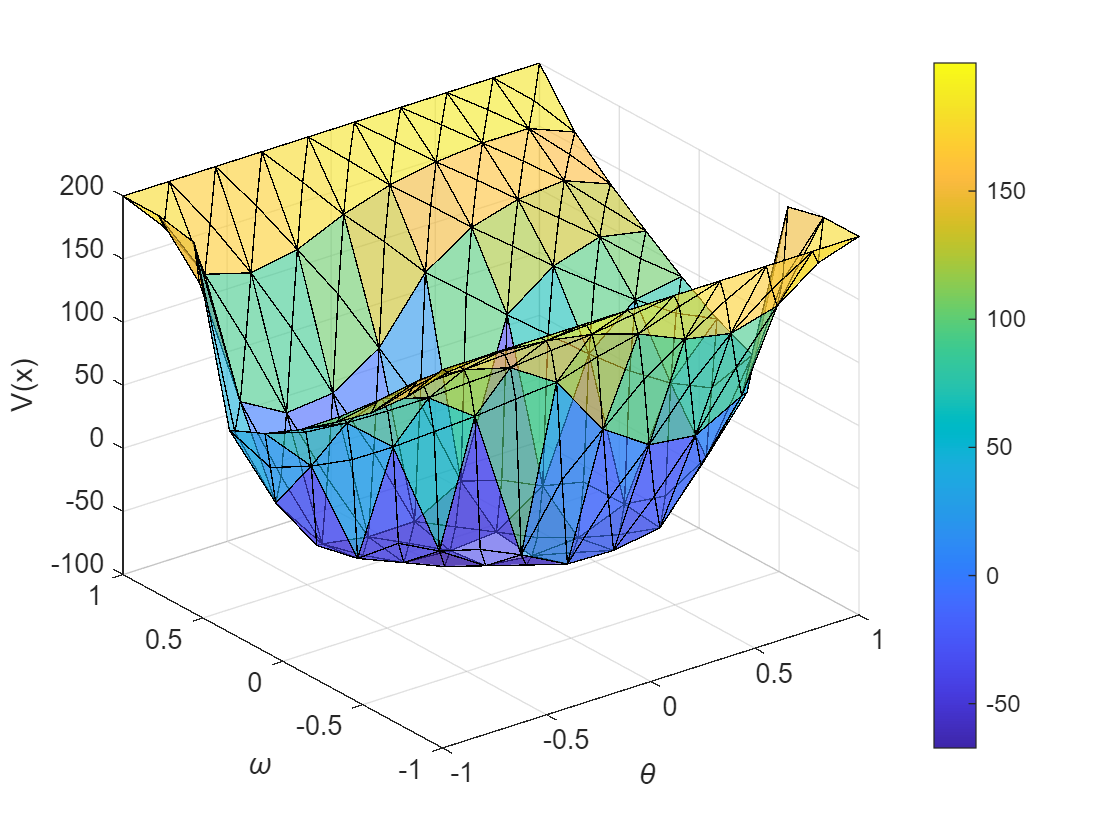

figure
trisurf(C,v(1,:),v(2,:),vals,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

In order to compare the results to the optimal solution, we print the optimal value of the optimisation function :


$$s^*_\eta := \underset{\{s_{i,c}\},\{\gamma_{d,c}\},\{b_c\}}\min \underset{i=1}\overset{3}\Sigma \underset{c=1}\overset{N_c}\Sigma s_{i,c} \ = \ \underset{i=1}\overset{3}\Sigma \underset{c=1}\overset{N_c}\Sigma -\eta \ = \ -3N_c.\eta$$


Then we print the value sum_ss of the optimisation function obtained for our solution, and we print the error between the two values.

fprintf('Computed optimal value : %f\n', -eta*length(C)*3)

Computed optimal value : -4800.000000


fprintf('Obtained optimal value : %f\n', sum_ss)

Obtained optimal value : -4516.838557


fprintf('Error : %f\n', sum_ss + eta*length(C)*3)

Error : 283.161443


**Step 4 :** validating the results.

In the optimisation problem, there is a variable to minimise that is supposed to insure that $\nabla V^Tf$ is negative. It is the slack variable ss, which in the constraint is noted $\{s_{i,c}\}\underset{c=1,...,N_c}\underset{i=1,2,3}
$, and we have $\nabla V^Tf \leq s$.

In this part, we check each slack variable in ss(3,$N_c$) to see if it is negative, and store its indices c and i along with its value in matrix bad_ind(~,3) if it is not.

clear bad_ind bad_triangles bad_points
bad_ind = [];
for c = 1: length(ss)
    for i = 1:3
        if ss(i,c) >= 0
            bad_ind = [bad_ind; [c, i, ss(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

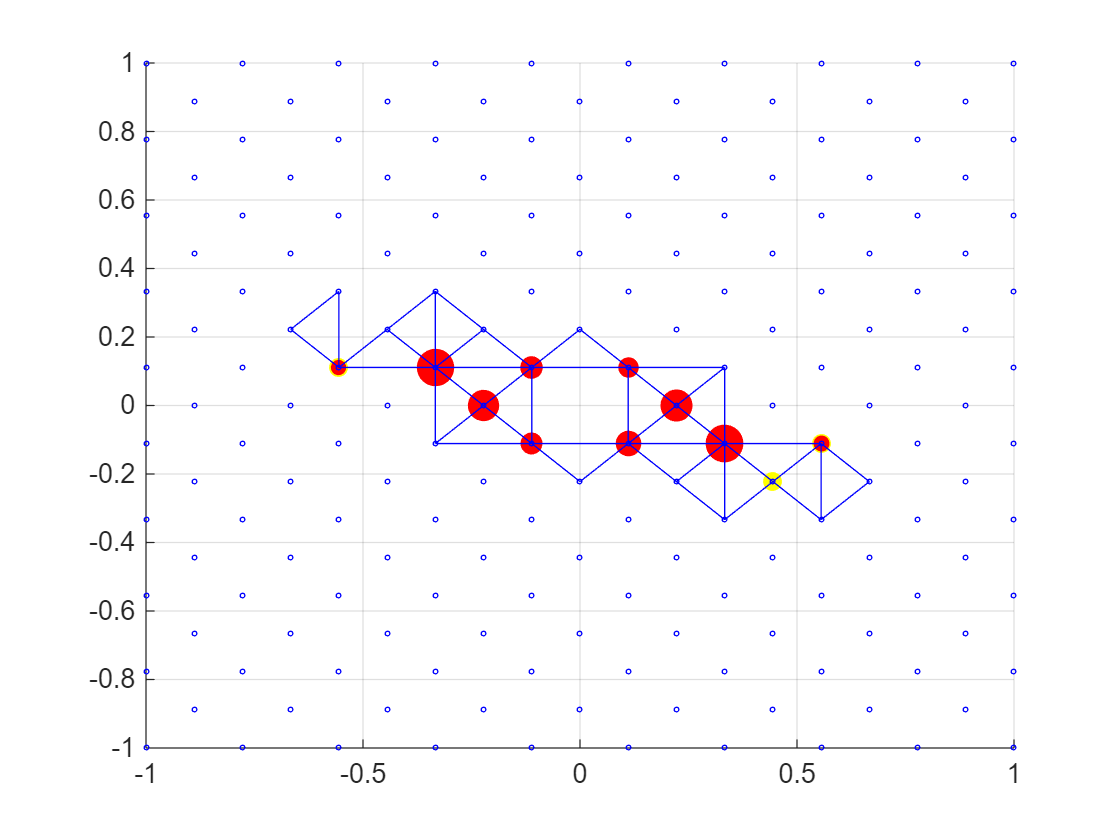

figure
if not(size(bad_ind)==0)
    bad_points = zeros(2, length(bad_ind(:,1)));
    bad_triangles = zeros(length(bad_ind(:,1)), 3);
    for ml = 1:length(bad_ind(:,1))
        bad_points(:,ml) = [v(1,C(bad_ind(ml,1),bad_ind(ml,2))); v(2,C(bad_ind(ml,1),bad_ind(ml,2)))]; % points' coordinates
        bad_triangles(ml,:) = C(bad_ind(ml,1),:); % triangles' indices
    end
    scatter(bad_points(1,:), bad_points(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points(1,:), bad_points(2,:), bad_ind(:,3).*200./max(bad_ind(:,3)), 'r', 'filled')
    triplot(bad_triangles, v(1,:), v(2,:))
end
scatter(v(1,:), v(2,:), 3, 'b')
grid on

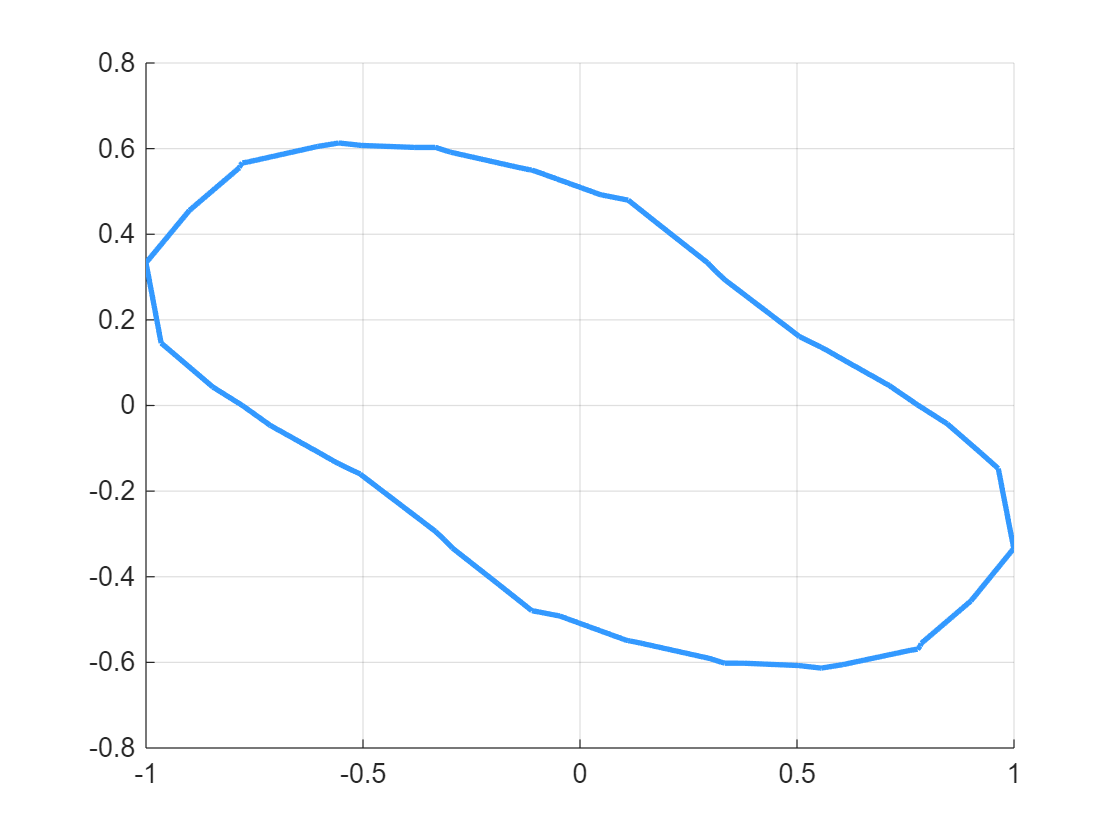

pointlist =    -0.9247    0.1111
   -0.8459    0.0430
   -0.7778   -0.0001
   -0.7134   -0.0467
   -0.5997   -0.1111
   -0.5717   -0.1273
   -0.5556   -0.1362
   -0.5066   -0.1601
   -0.4365   -0.2142
   -0.3333   -0.2938


[pointlist,alpha] = sublevelset(dX,C,v,gs,bs,vals,1,[.2 .6 1])

creating new vertices... 


k = 1.4800

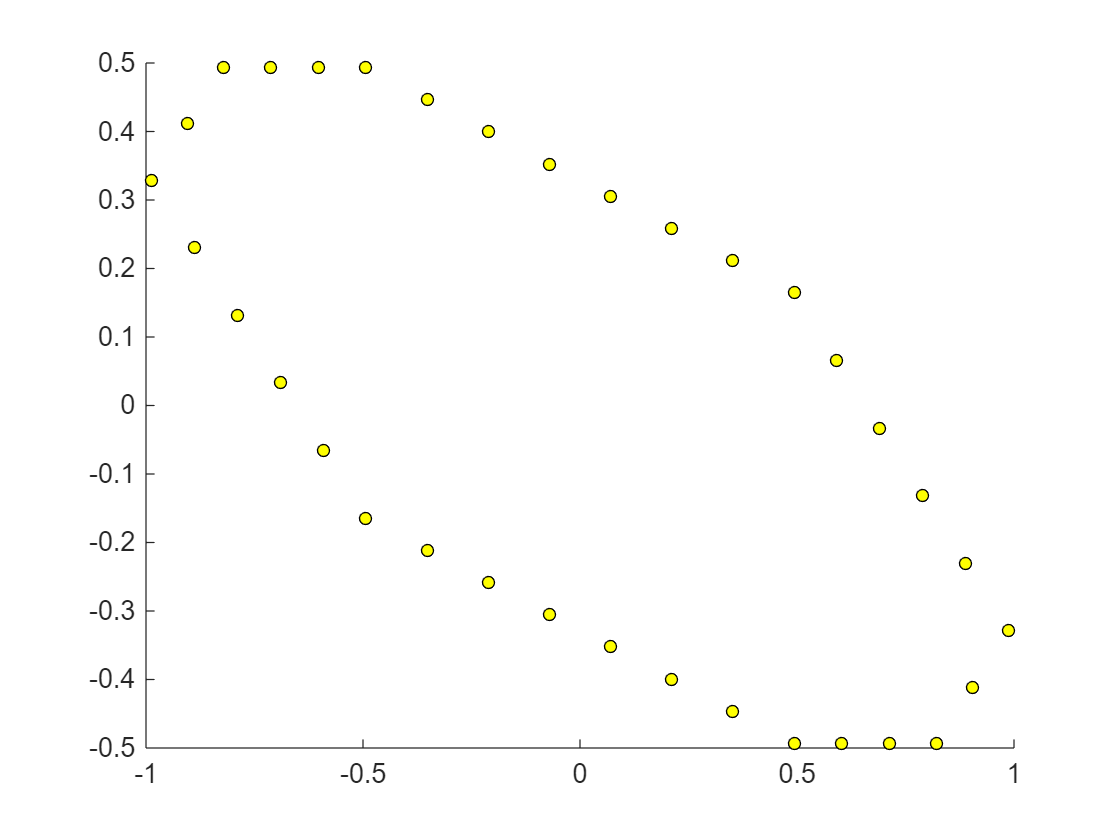

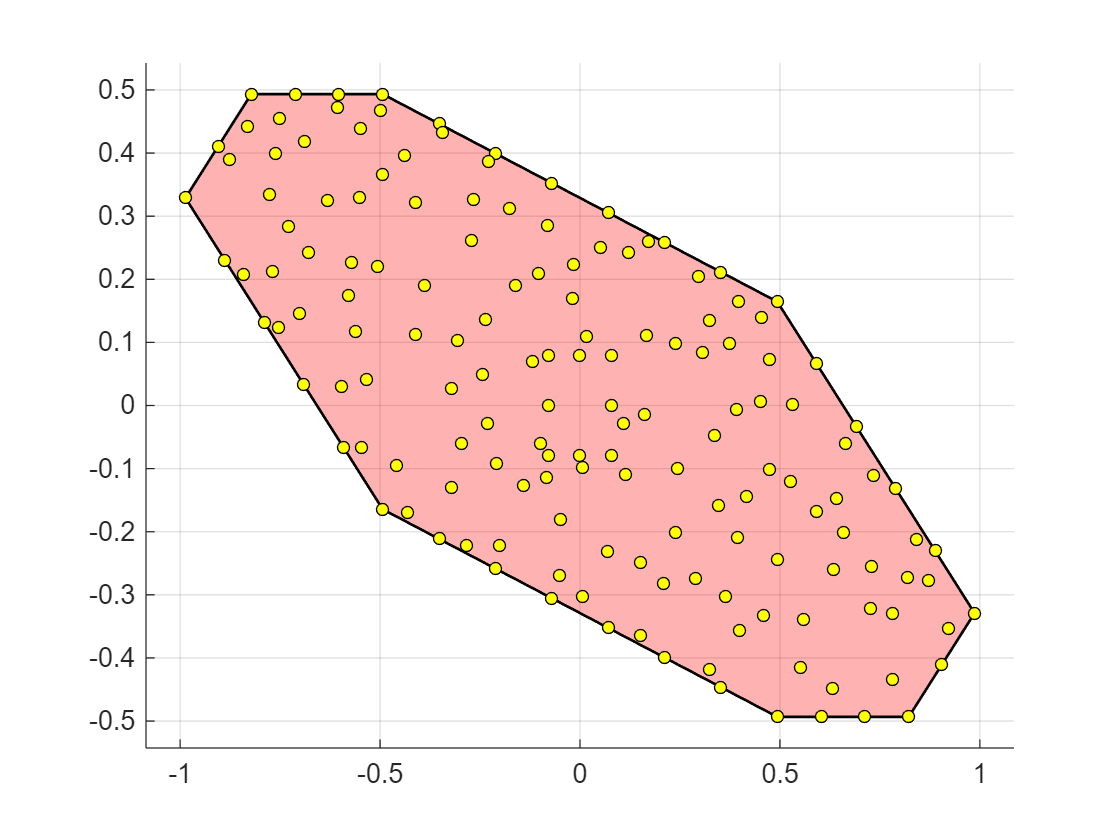

Elapsed time is 0.067076 seconds.
vertices created
 
Elapsed time is 0.069802 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 1.293690 seconds.
tessellation cleaning ended
 


clear v_new C_new Tess_new
[v_new,C_new,Nv_new,Nc_new,dX_new,Tess_new,beta_new] = TessellationFinderV3(250,v,bad_triangles,0.8*l_A,'random',pointlist,0.025);

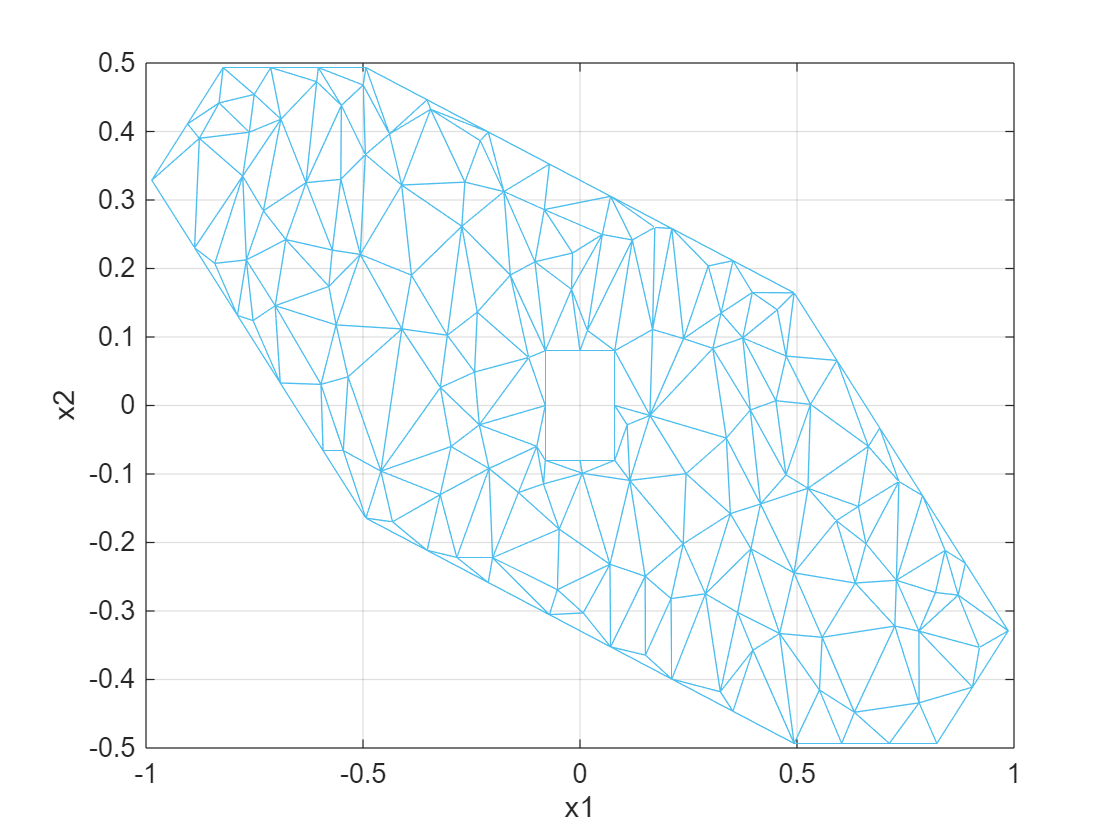


figure
triplot(C_new, v_new(1,:), v_new(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

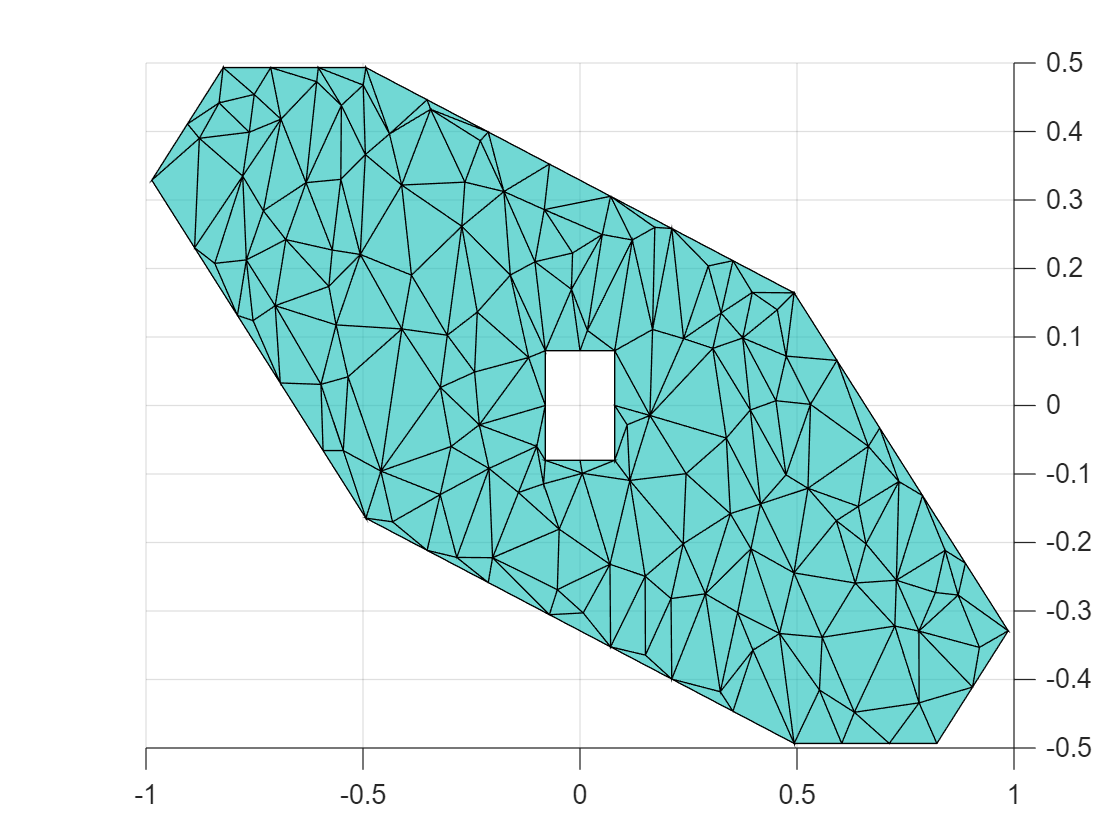

figure
trisurf(C_new,v_new(1,:),v_new(2,:),zeros(length(v_new),1),'FaceAlpha',.6)
grid on

l_new = [min(v_new(1,:)),max(v_new(1,:));min(v_new(2,:)),max(v_new(2,:))];
[x_new,f_new,Nd_new] = DataGenerator(350,sample_ratio,l_new,v_new,Tess_new,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

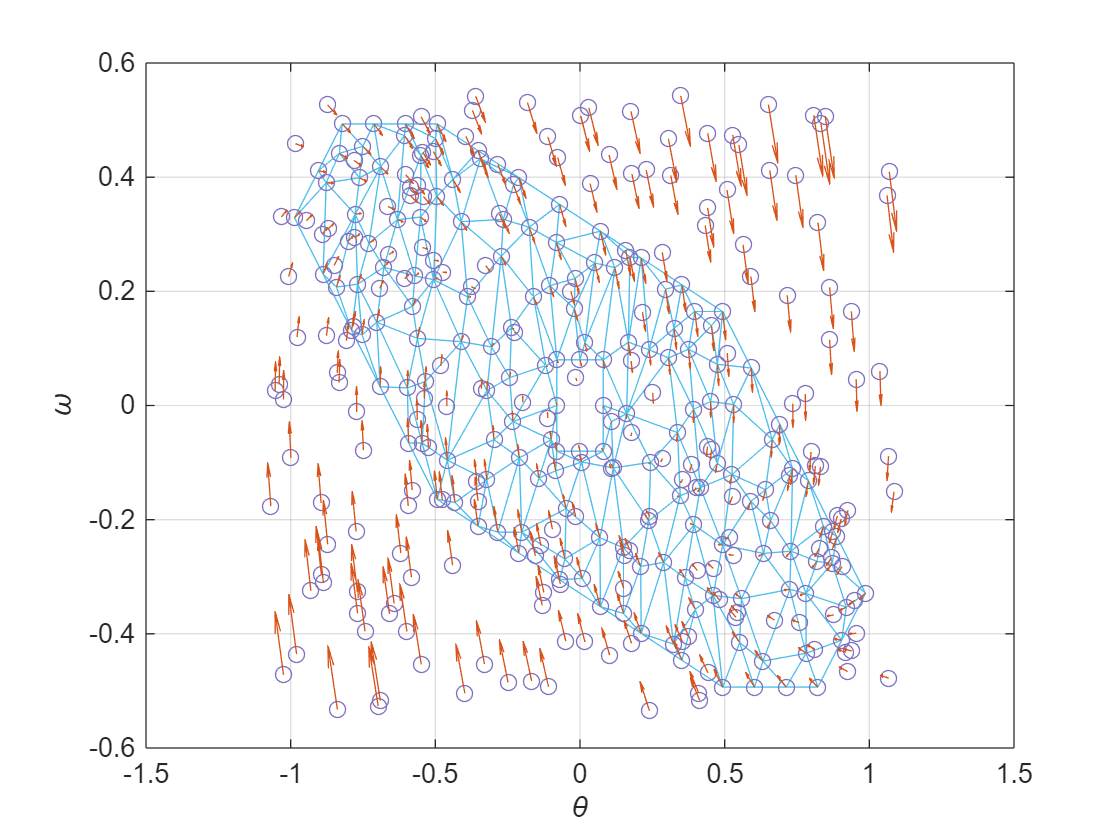

figure
triplot(C_new, v_new(1,:), v_new(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new(1,:), x_new(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new(1,:), x_new(2,:), f_new(1,:), f_new(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new bs_new vals_new ss_new sum_ss_new
[gs_new,bs_new,vals_new,ss_new,sum_ss_new] = OptimisationProblem(x_new,f_new,M,v_new,C_new,eps,eta,upperlim,lowerlim,dA,dX_new,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 282
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 3.0119e+03
       solvertime: 66.1871
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 3155.620018 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new)*3)

Computed optimal value : -4230.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new)

Obtained optimal value : -3986.239817


fprintf('Error : %f\n', sum_ss_new + eta*length(C_new)*3)

Error : 243.760183


We plot the solution in 3D, each triangle is plotted independently from the others.

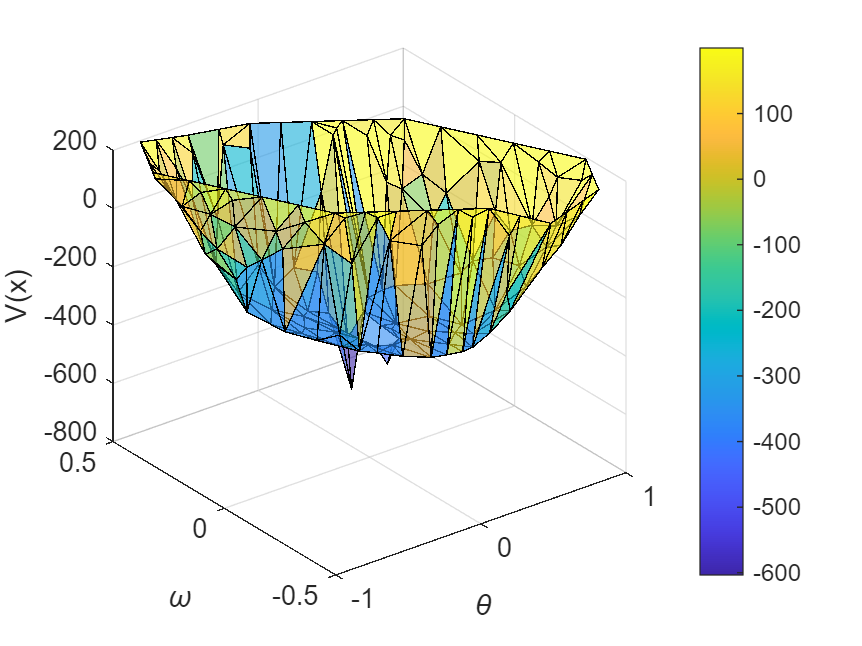

figure
trisurf(C_new,v_new(1,:),v_new(2,:),vals_new,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new bad_triangles_new bad_points_new
bad_ind_new = [];
for c = 1: length(ss_new)
    for i = 1:3
        if ss_new(i,c) >= 0
            bad_ind_new = [bad_ind_new; [c, i, ss_new(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

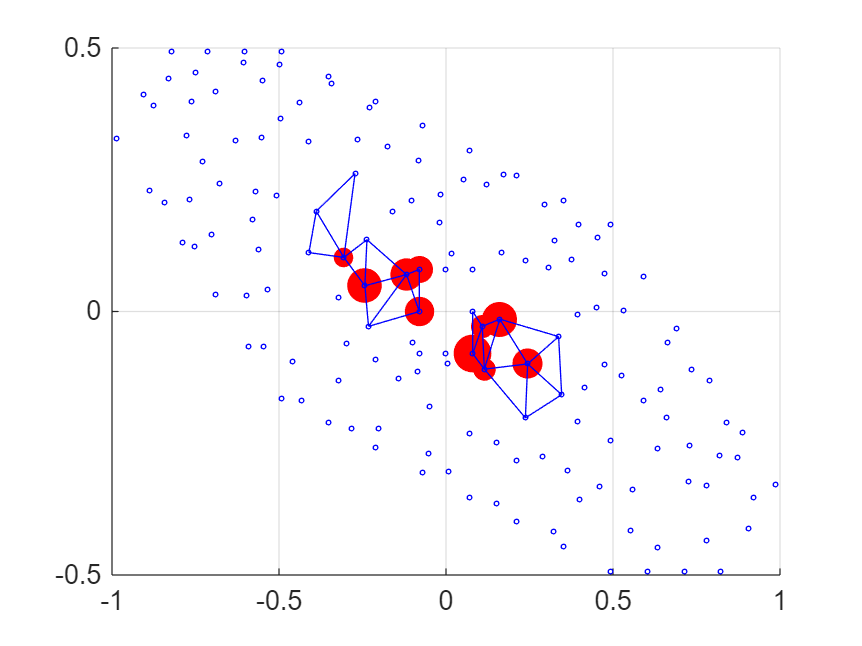

figure
if not(size(bad_ind_new)==0)
    bad_points_new = zeros(2, length(bad_ind_new(:,1)));
    bad_triangles_new = zeros(length(bad_ind_new(:,1)), 3);
    for ml = 1:length(bad_ind_new(:,1))
        bad_points_new(:,ml) = [v_new(1,C_new(bad_ind_new(ml,1),bad_ind_new(ml,2))); v_new(2,C_new(bad_ind_new(ml,1),bad_ind_new(ml,2)))]; % points' coordinates
        bad_triangles_new(ml,:) = C_new(bad_ind_new(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new(1,:), bad_points_new(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new(1,:), bad_points_new(2,:), bad_ind_new(:,3).*200./max(bad_ind_new(:,3)), 'r', 'filled')
    triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
end
scatter(v_new(1,:), v_new(2,:), 3, 'b')
grid on

[pointlist_new,alpha_new] = sublevelset(dX_new,C_new,v_new,gs_new,bs_new,vals_new,1,[.2 .6 1])

pointlist_new =     0.3944    0.1571
    0.4525    0.1387
    0.4553    0.1372
    0.4860    0.1276
    0.5453    0.0683
    0.5731    0.0459
    0.6485   -0.0321
    0.6701   -0.0538
    0.7293   -0.1012
    0.7416   -0.1136


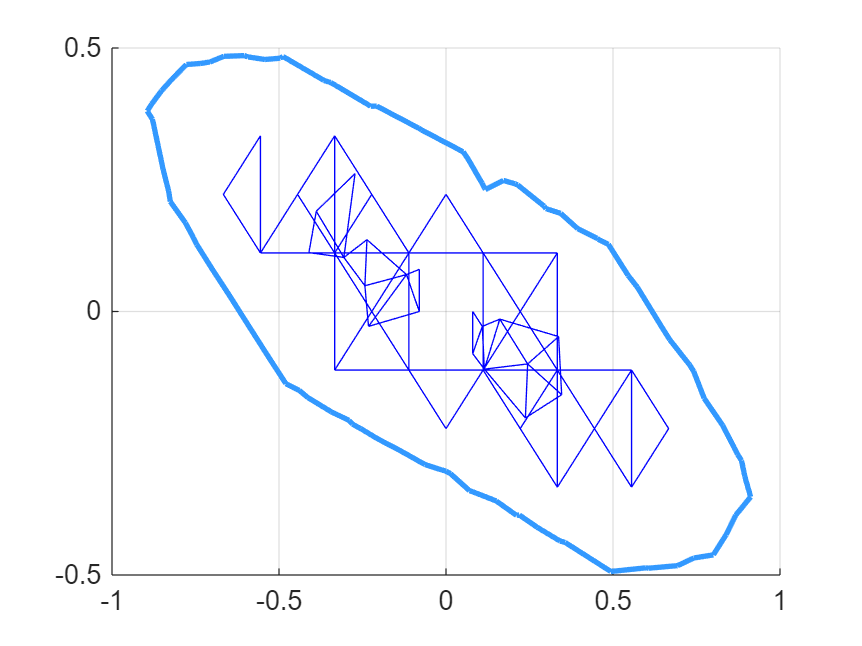

triplot(bad_triangles, v(1,:), v(2,:))
triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
grid on

creating new vertices... 


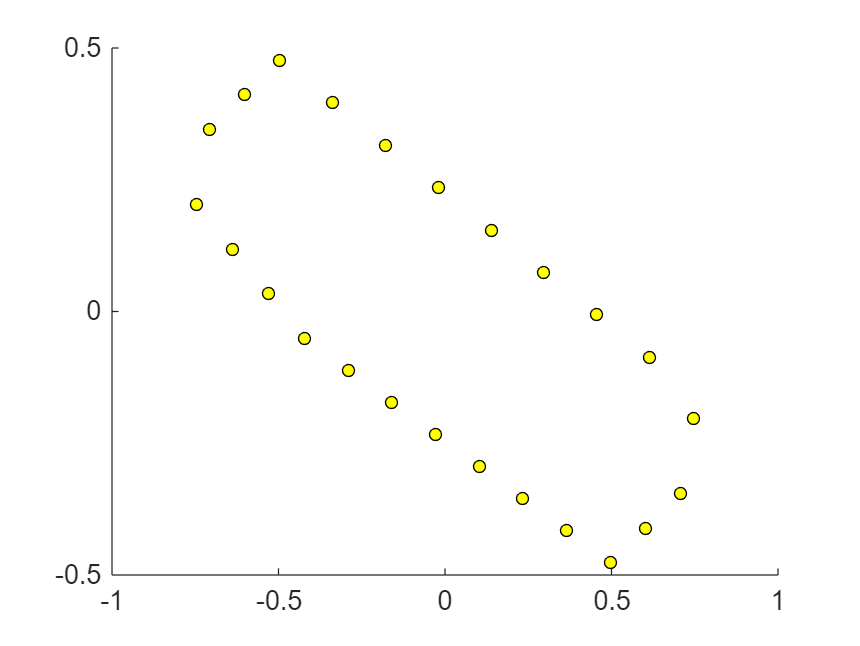

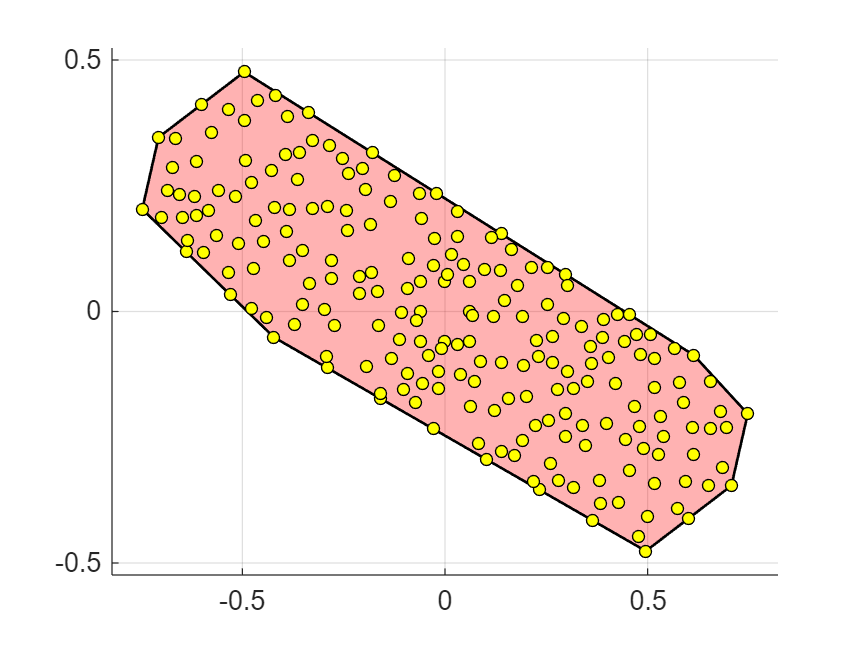

Elapsed time is 0.060031 seconds.
vertices created
 
Elapsed time is 0.062868 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 1.367312 seconds.
tessellation cleaning ended
 


[v_new1,C_new1,Nv_new1,Nc_new1,dX_new1,Tess_new1,beta_new1] = TessellationFinderV3(200,v_new,bad_triangles_new,0.6*l_A,'random',pointlist_new,0.02);

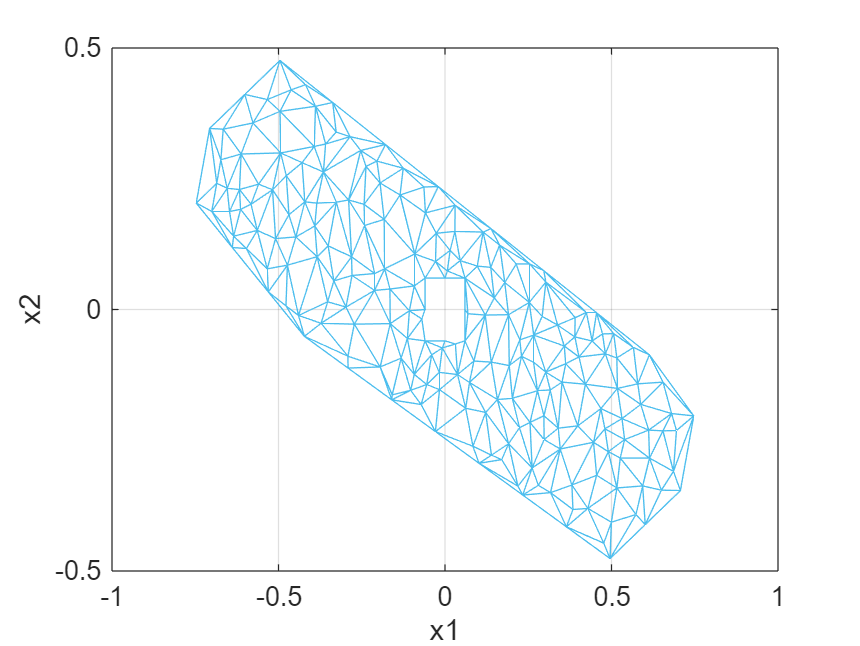

figure
triplot(C_new1, v_new1(1,:), v_new1(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

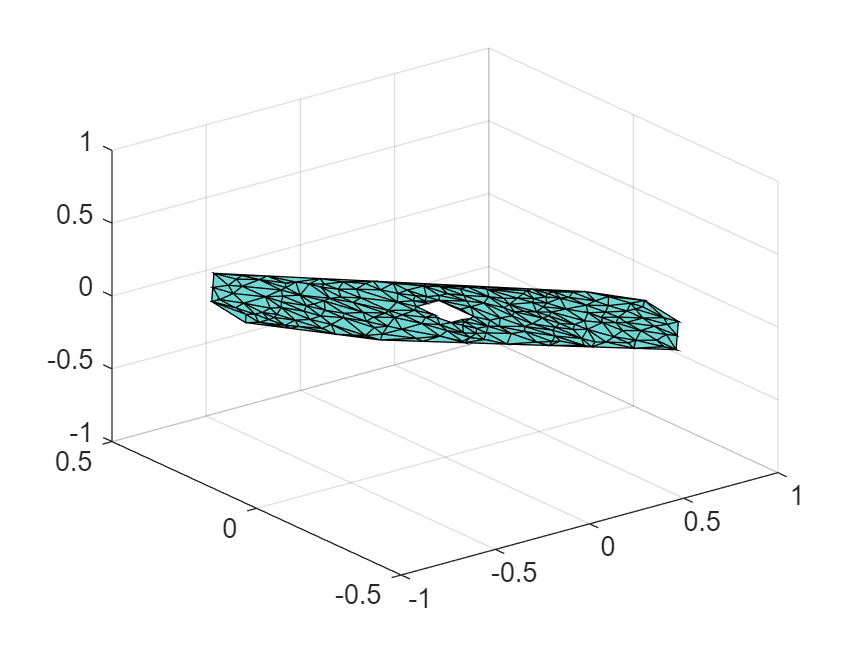

figure
trisurf(C_new1,v_new1(1,:),v_new1(2,:),zeros(length(v_new1),1),'FaceAlpha',.6)
grid on

l_new1 = [min(v_new1(1,:)),max(v_new1(1,:));min(v_new1(2,:)),max(v_new1(2,:))];
[x_new1,f_new1,Nd_new1] = DataGenerator(350,sample_ratio,l_new1,v_new1,Tess_new1,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

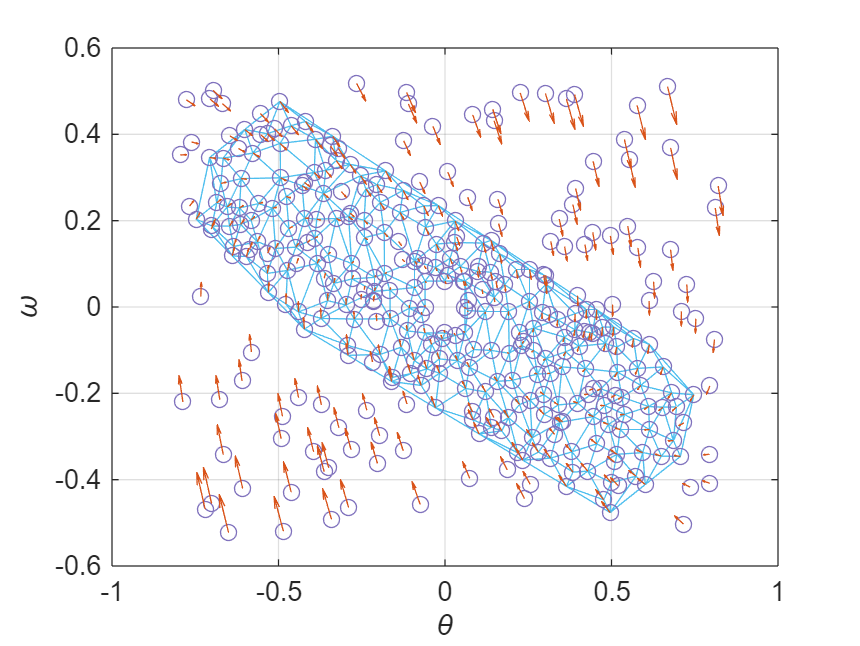

figure
triplot(C_new1, v_new1(1,:), v_new1(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new1(1,:), x_new1(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new1(1,:), x_new1(2,:), f_new1(1,:), f_new1(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new1 bs_new1 vals_new1 ss_new1 sum_ss_new1
[gs_new1,bs_new1,vals_new1,ss_new1,sum_ss_new1] = OptimisationProblem(x_new1,f_new1,M,v_new1,C_new1,eps,eta,upperlim,lowerlim,dA,dX_new1,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 386
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 3.2524e+03
       solvertime: 77.8888
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 3468.244769 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new1)*3)

Computed optimal value : -5790.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new1)

Obtained optimal value : -5584.907296


fprintf('Error : %f\n', sum_ss_new1 + eta*length(C_new1)*3)

Error : 205.092704


We plot the solution in 3D, each triangle is plotted independently from the others.

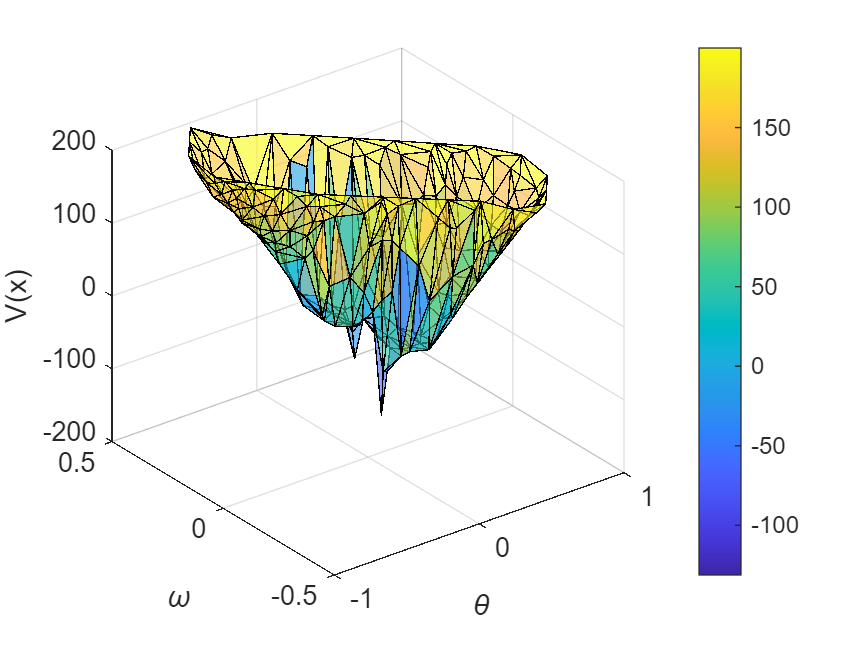

figure
trisurf(C_new1,v_new1(1,:),v_new1(2,:),vals_new1,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new1 bad_triangles_new1 bad_points_new1
bad_ind_new1 = [];
for c = 1:length(ss_new1)
    for i = 1:3
        if ss_new1(i,c) >= 0
            bad_ind_new1 = [bad_ind_new1; [c, i, ss_new1(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

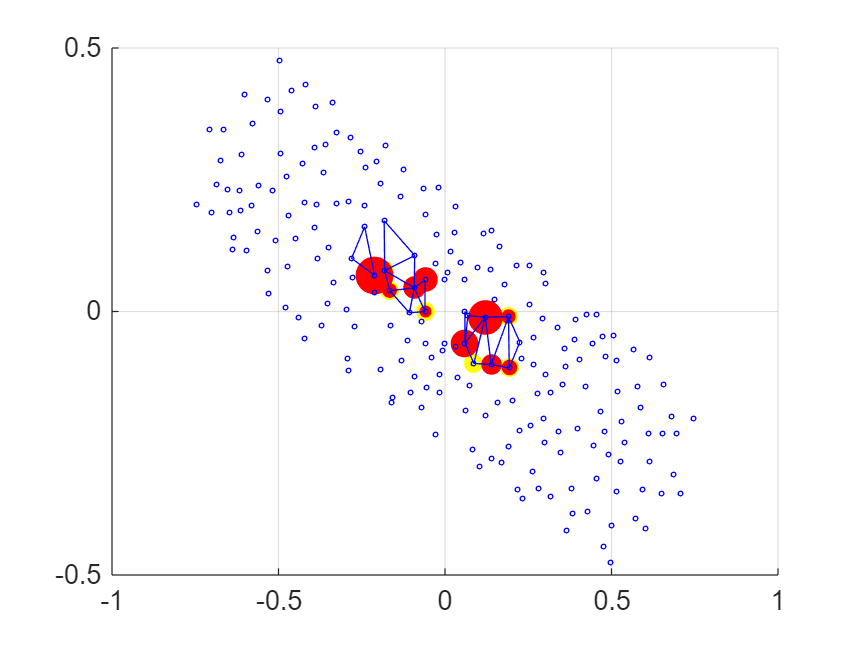

figure
if not(size(bad_ind_new1)==0)
    bad_points_new1 = zeros(2, length(bad_ind_new1(:,1)));
    bad_triangles_new1 = zeros(length(bad_ind_new1(:,1)), 3);
    for ml = 1:length(bad_ind_new1(:,1))
        bad_points_new1(:,ml) = [v_new1(1,C_new1(bad_ind_new1(ml,1),bad_ind_new1(ml,2))); v_new1(2,C_new1(bad_ind_new1(ml,1),bad_ind_new1(ml,2)))]; % points' coordinates
        bad_triangles_new1(ml,:) = C_new1(bad_ind_new1(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new1(1,:), bad_points_new1(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new1(1,:), bad_points_new1(2,:), bad_ind_new1(:,3).*200./max(bad_ind_new1(:,3)), 'r', 'filled')
    triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
end
scatter(v_new1(1,:), v_new1(2,:), 3, 'b')
grid on

[pointlist_new1,alpha_new1] = sublevelset(dX_new1,C_new1,v_new1,gs_new1,bs_new1,vals_new1,1,[.2 .6 1])

pointlist_new1 =    -0.3372    0.3958
   -0.3372    0.3958
   -0.3372    0.3958
   -0.4153    0.4249
   -0.4301    0.4273
   -0.4792    0.4485
   -0.5184    0.4316
   -0.5609    0.4054
   -0.5954    0.3981
   -0.6323    0.3794


alpha_new1 = 189.6801

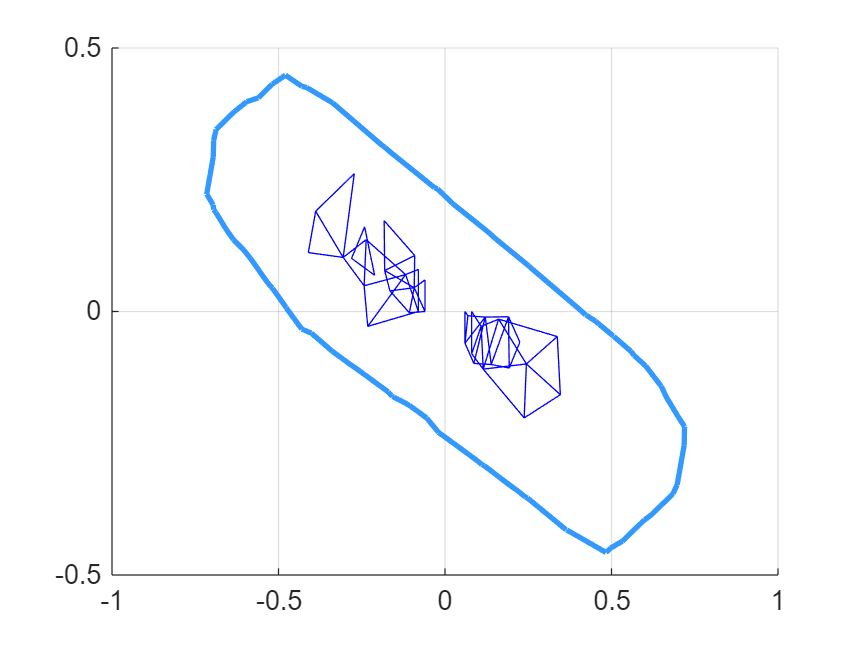

triplot(bad_triangles_new, v_new(1,:), v_new(2,:))
triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
grid on

creating new vertices... 


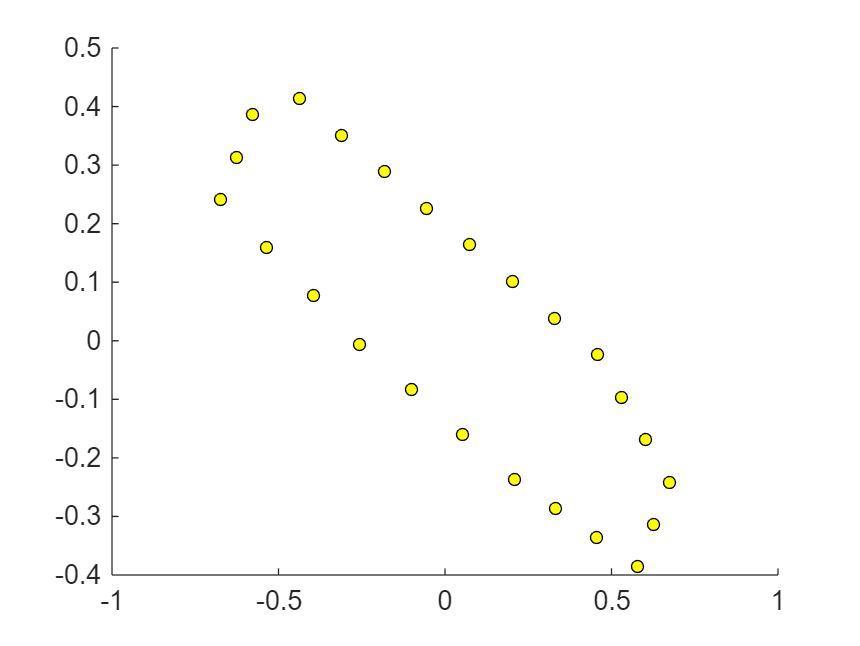

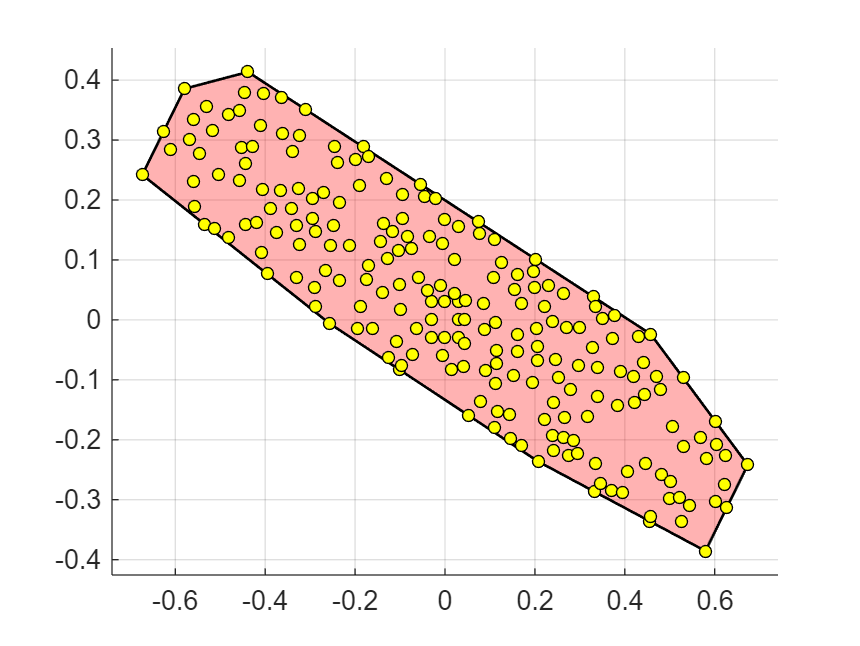

Elapsed time is 0.197909 seconds.
vertices created
 
Elapsed time is 0.201068 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 1.487836 seconds.
tessellation cleaning ended
 


[v_new2,C_new2,Nv_new2,Nc_new2,dX_new2,Tess_new2,beta_new2] = TessellationFinderV3(200,v_new1,bad_triangles_new1,0.3*l_A,'random',pointlist_new1,0.015);

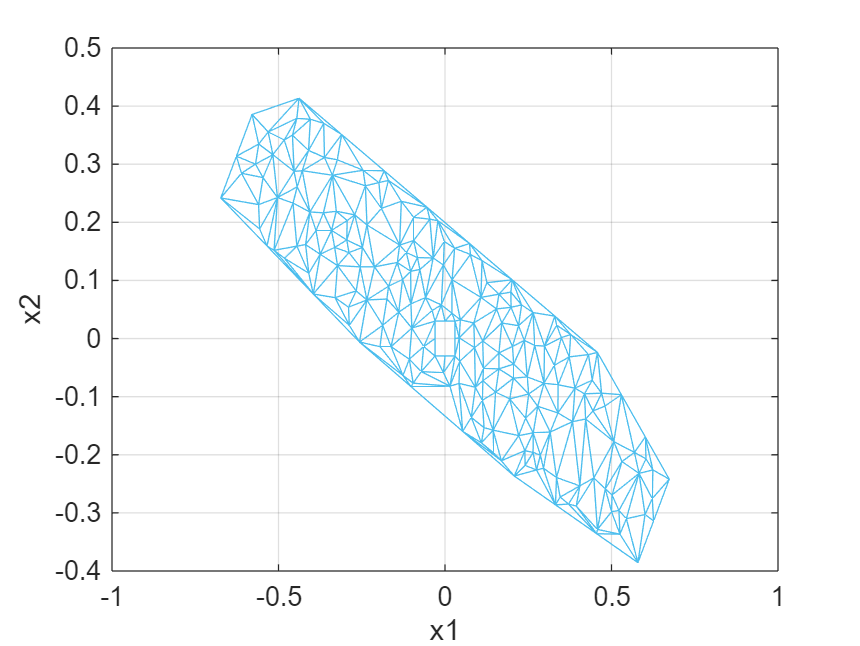

figure
triplot(C_new2, v_new2(1,:), v_new2(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

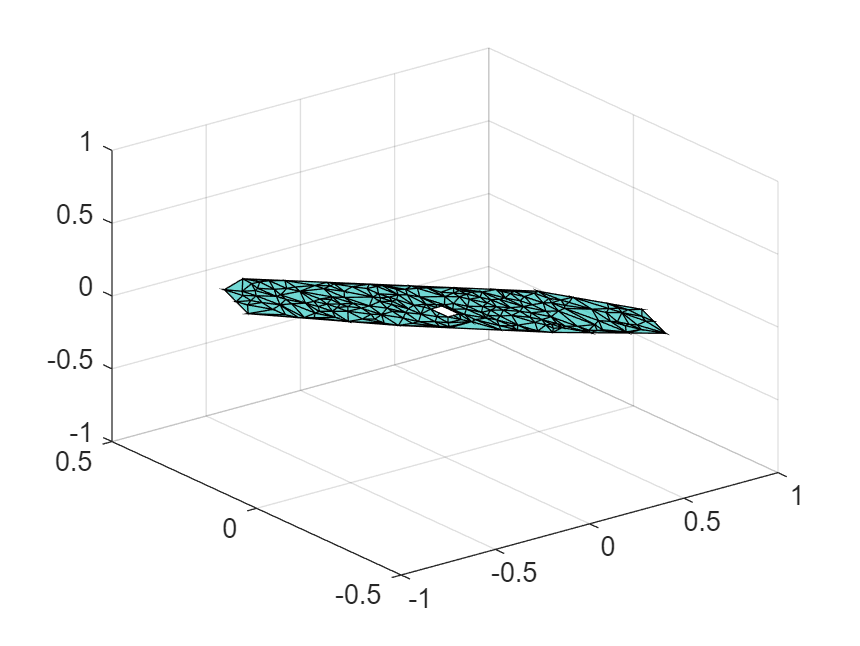

figure
trisurf(C_new2,v_new2(1,:),v_new2(2,:),zeros(length(v_new2),1),'FaceAlpha',.6)
grid on

l_new2 = [min(v_new2(1,:)),max(v_new2(1,:));min(v_new2(2,:)),max(v_new2(2,:))];
[x_new2,f_new2,Nd_new2] = DataGenerator(350,sample_ratio,l_new2,v_new2,Tess_new2,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

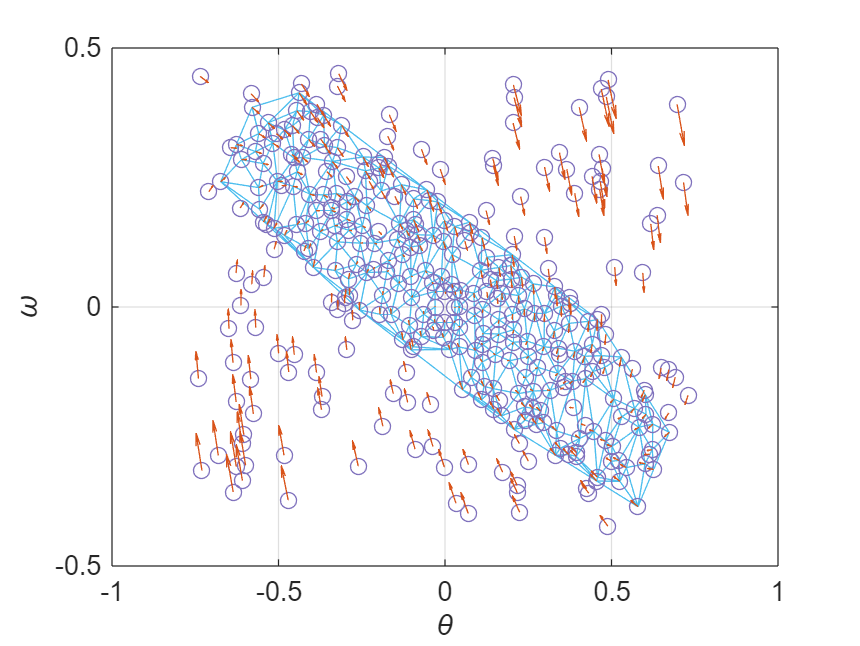

figure
triplot(C_new2, v_new2(1,:), v_new2(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new2(1,:), x_new2(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new2(1,:), x_new2(2,:), f_new2(1,:), f_new2(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new2 bs_new2 vals_new2 ss_new2 sum_ss_new2
[gs_new2,bs_new2,vals_new2,ss_new2,sum_ss_new2] = OptimisationProblem(x_new2,f_new2,M,v_new2,C_new2,eps,eta,alpha,beta,dA,dX_new2,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 390
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 2.7024e+03
       solvertime: 103.4773
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 2945.438113 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new2)*3)

Computed optimal value : -5850.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new2)

Obtained optimal value : -5630.733887


fprintf('Error : %f\n', sum_ss_new2 + eta*length(C_new2)*3)

Error : 219.266113


We plot the solution in 3D, each triangle is plotted independently from the others.

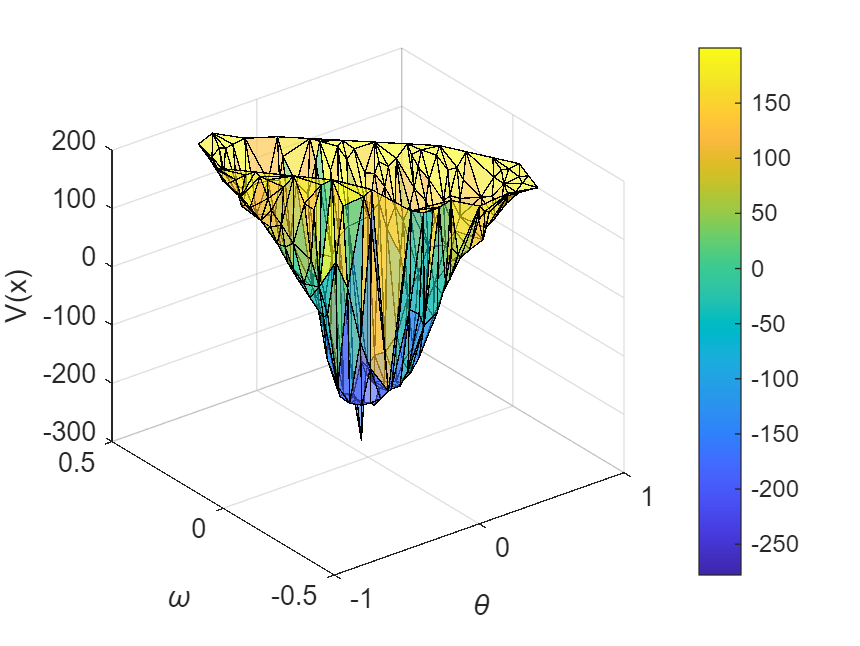

figure
trisurf(C_new2,v_new2(1,:),v_new2(2,:),vals_new2,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new2 bad_triangles_new2 bad_points_new2
bad_ind_new2 = [];
for c = 1:length(ss_new2)
    for i = 1:3
        if ss_new2(i,c) >= 0
            bad_ind_new2 = [bad_ind_new2; [c, i, ss_new2(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

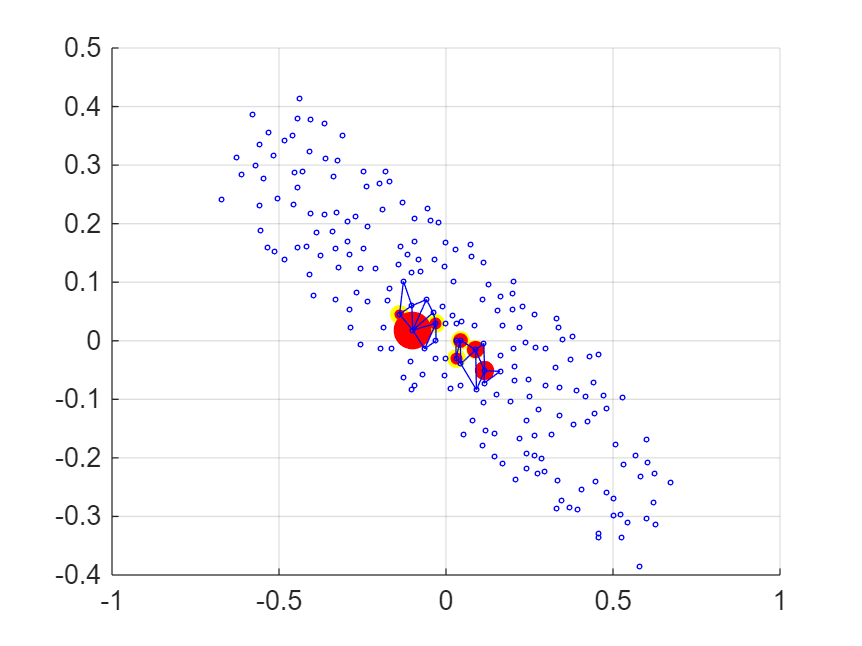

figure
if not(size(bad_ind_new2)==0)
    bad_points_new2 = zeros(2, length(bad_ind_new2(:,1)));
    bad_triangles_new2 = zeros(length(bad_ind_new2(:,1)), 3);
    for ml = 1:length(bad_ind_new2(:,1))
        bad_points_new2(:,ml) = [v_new2(1,C_new2(bad_ind_new2(ml,1),bad_ind_new2(ml,2))); v_new2(2,C_new2(bad_ind_new2(ml,1),bad_ind_new2(ml,2)))]; % points' coordinates
        bad_triangles_new2(ml,:) = C_new2(bad_ind_new2(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new2(1,:), bad_points_new2(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new2(1,:), bad_points_new2(2,:), bad_ind_new2(:,3).*200./max(bad_ind_new2(:,3)), 'r', 'filled')
    triplot(bad_triangles_new2, v_new2(1,:), v_new2(2,:))
end
scatter(v_new2(1,:), v_new2(2,:), 3, 'b')
grid on

[pointlist_new2,alpha_new2] = sublevelset(dX_new2,C_new2,v_new2,gs_new2,bs_new2,vals_new2,1,[.2 .6 1])

pointlist_new2 =    -0.4794    0.3359
   -0.4949    0.3328
   -0.5200    0.3247
   -0.5253    0.3200
   -0.5342    0.3111
   -0.5472    0.2777
   -0.5476    0.2770
   -0.5468    0.2756
   -0.5321    0.2365
   -0.5216    0.2241


alpha_new2 = 154.4372

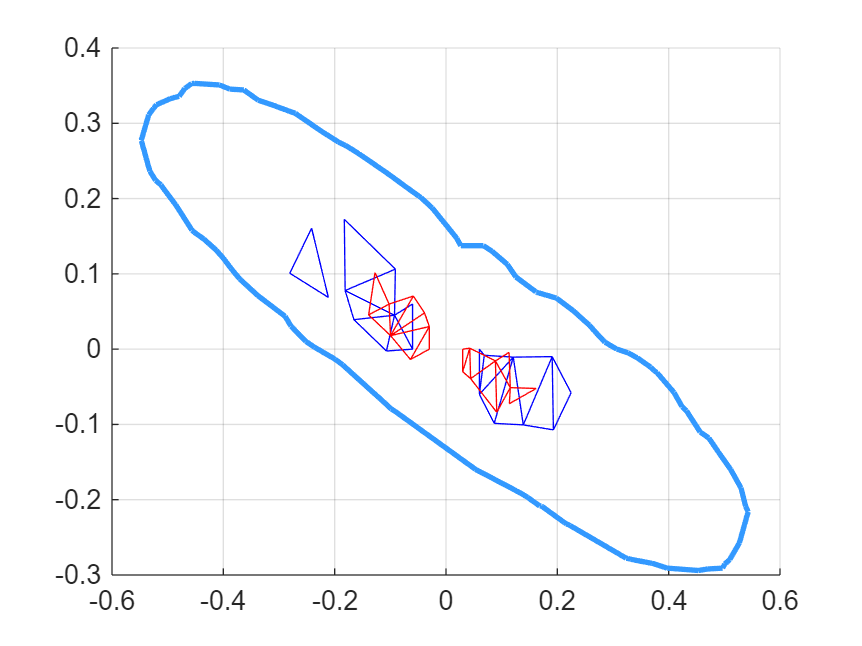

triplot(bad_triangles_new1, v_new1(1,:), v_new1(2,:))
triplot(bad_triangles_new2, v_new2(1,:), v_new2(2,:),'r')
grid on

creating new vertices... 


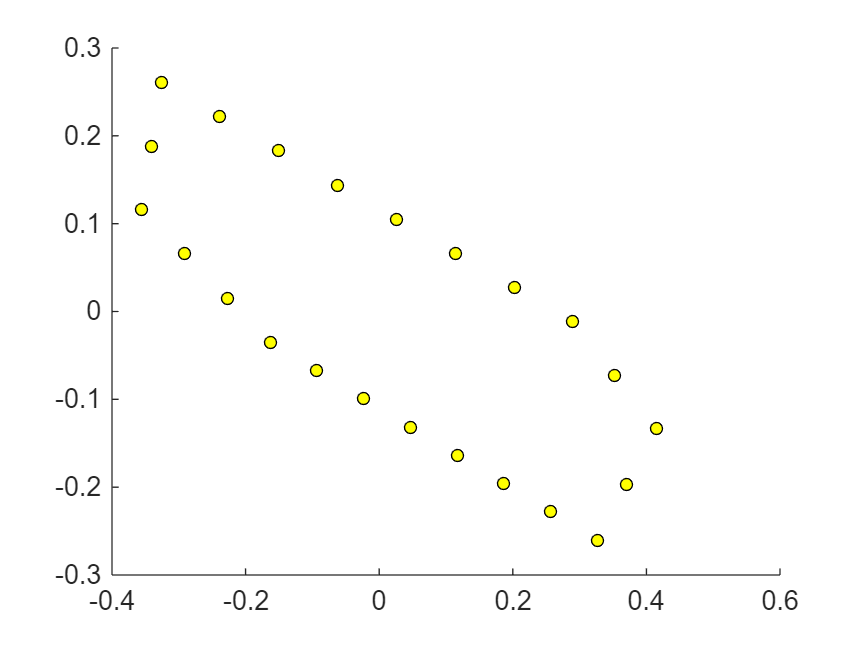

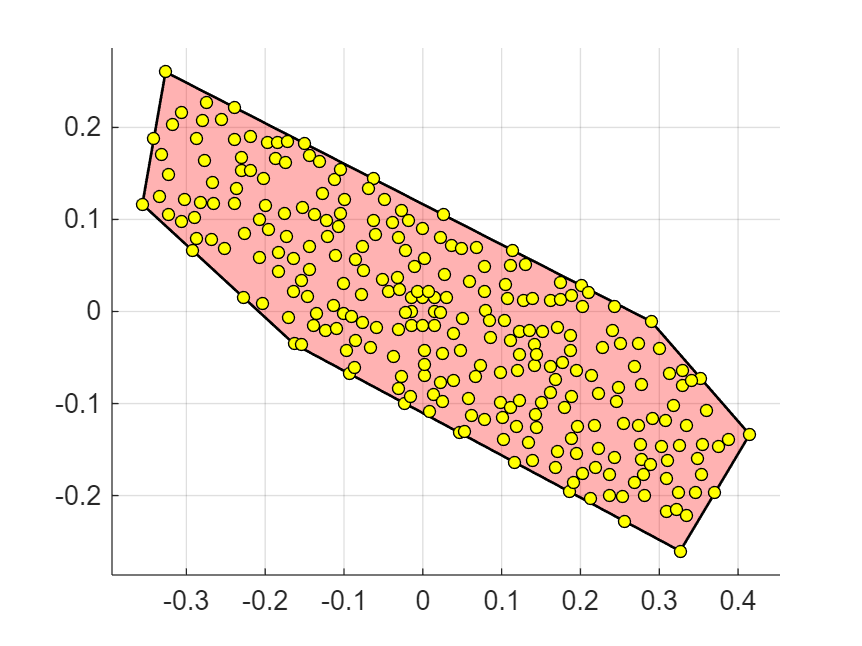

Elapsed time is 0.030565 seconds.
vertices created
 
Elapsed time is 0.033676 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 1.315827 seconds.
tessellation cleaning ended
 


[v_new3,C_new3,Nv_new3,Nc_new3,dX_new3,Tess_new3,beta_new3] = TessellationFinderV3(250,v_new2,bad_triangles_new2,0.15*l_A,'random',pointlist_new2,0.013);

[pointlist_new2,~] = sublevelset(dX_new2,C_new2,v_new2,gs_new2,bs_new2,vals_new2,1,[.2 .6 1])

pointlist_new2 =    -0.4794    0.3359
   -0.4949    0.3328
   -0.5200    0.3247
   -0.5253    0.3200
   -0.5342    0.3111
   -0.5472    0.2777
   -0.5476    0.2770
   -0.5468    0.2756
   -0.5321    0.2365
   -0.5216    0.2241


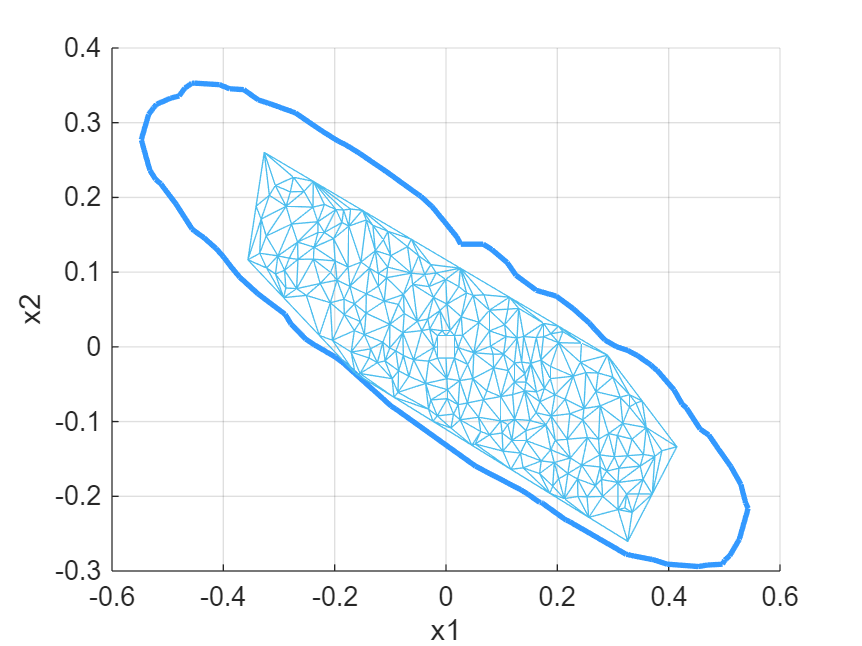

triplot(C_new3, v_new3(1,:), v_new3(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

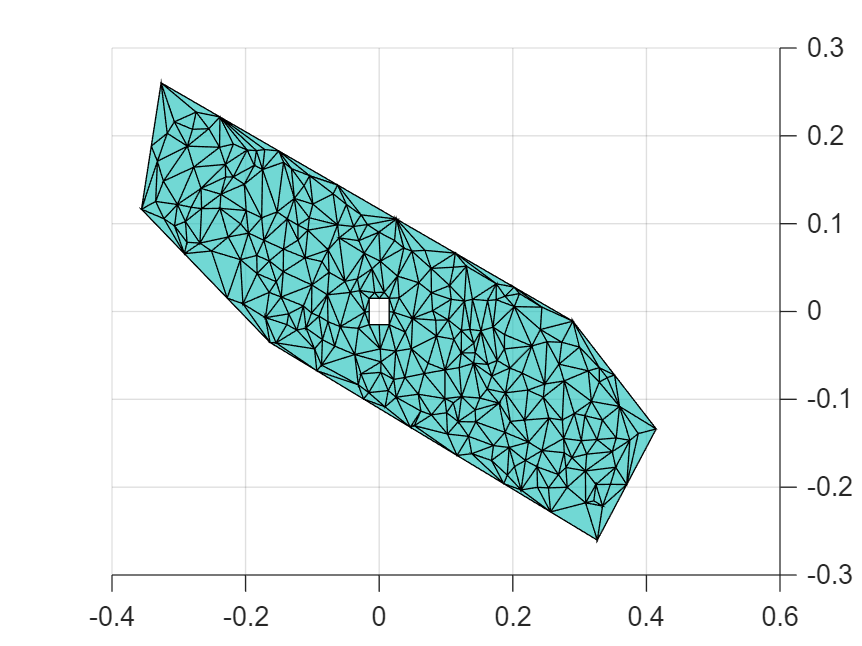

figure
trisurf(C_new3,v_new3(1,:),v_new3(2,:),zeros(length(v_new3),1),'FaceAlpha',.6)
grid on

l_new3 = [min(v_new3(1,:)),max(v_new3(1,:));min(v_new3(2,:)),max(v_new3(2,:))];
[x_new3,f_new3,Nd_new3] = DataGenerator(370,sample_ratio,l_new3,v_new3,Tess_new3,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

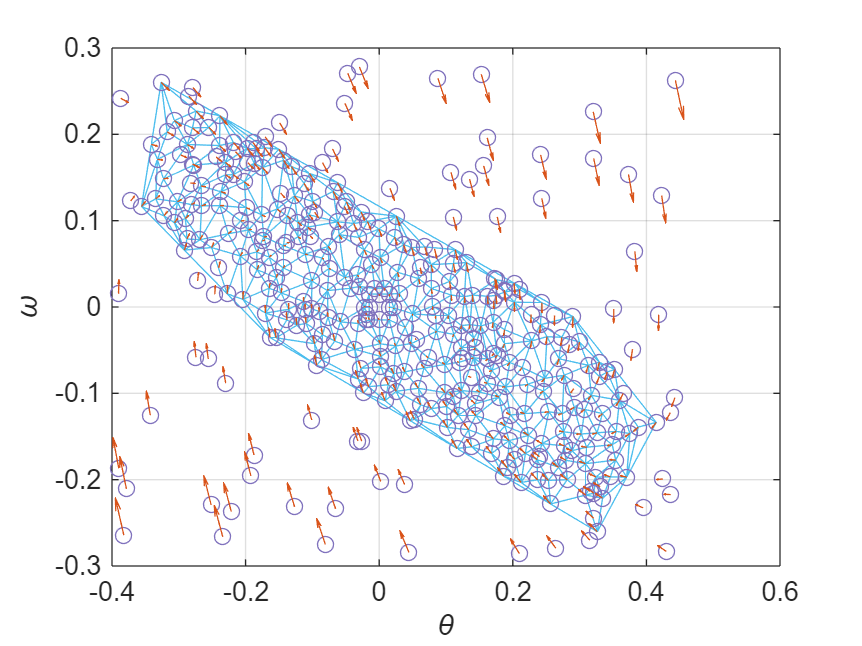

figure
triplot(C_new3, v_new3(1,:), v_new3(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new3(1,:), x_new3(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new3(1,:), x_new3(2,:), f_new3(1,:), f_new3(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new3 bs_new3 vals_new3 ss_new3 sum_ss_new3
[gs_new3,bs_new3,vals_new3,ss_new3,sum_ss_new3] = OptimisationProblem(x_new3,f_new3,M,v_new3,C_new3,eps,eta,alpha,beta,dA,dX_new3,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 509
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 5.0853e+03
       solvertime: 130.6793
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 5420.027357 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new3)*3)

Computed optimal value : -7635.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new3)

Obtained optimal value : -7262.321982


fprintf('Error : %f\n', sum_ss_new3 + eta*length(C_new3)*3)

Error : 372.678018


We plot the solution in 3D, each triangle is plotted independently from the others.

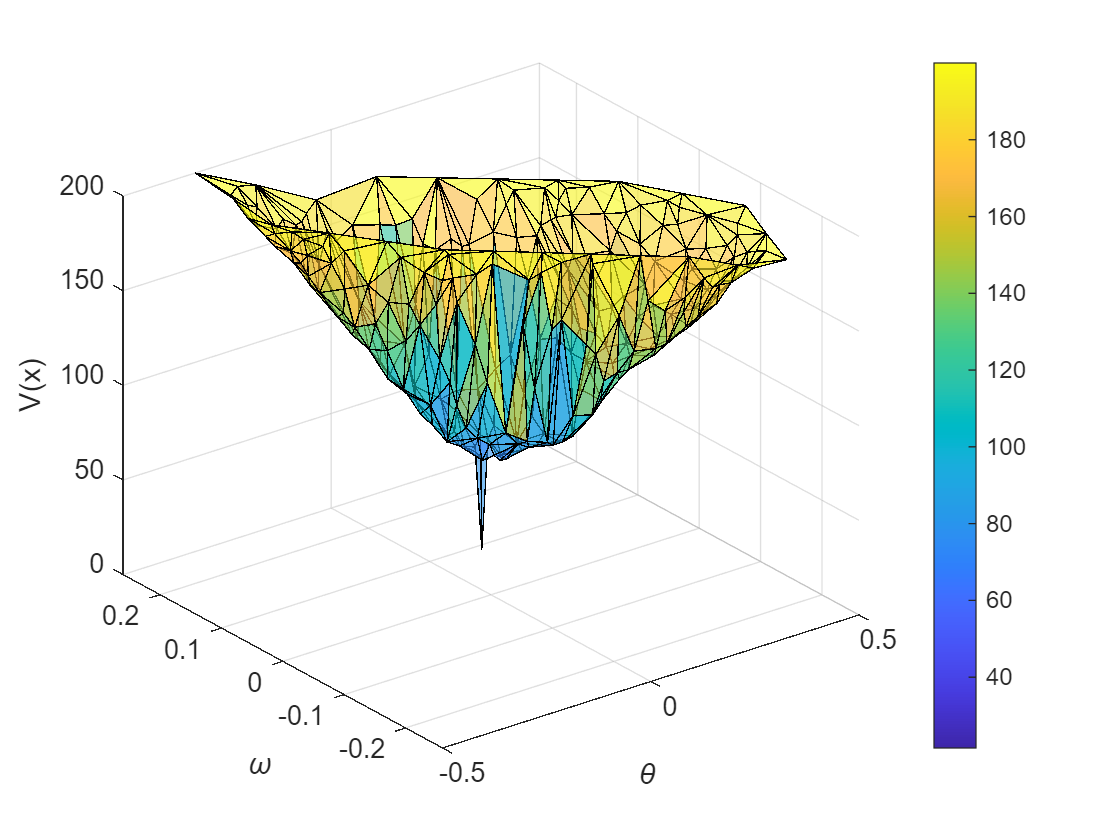

figure
trisurf(C_new3,v_new3(1,:),v_new3(2,:),vals_new3,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new3 bad_triangles_new3 bad_points_new3
bad_ind_new3 = [];
for c = 1:length(ss_new3)
    for i = 1:3
        if ss_new3(i,c) >= 0
            bad_ind_new3 = [bad_ind_new3; [c, i, ss_new3(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

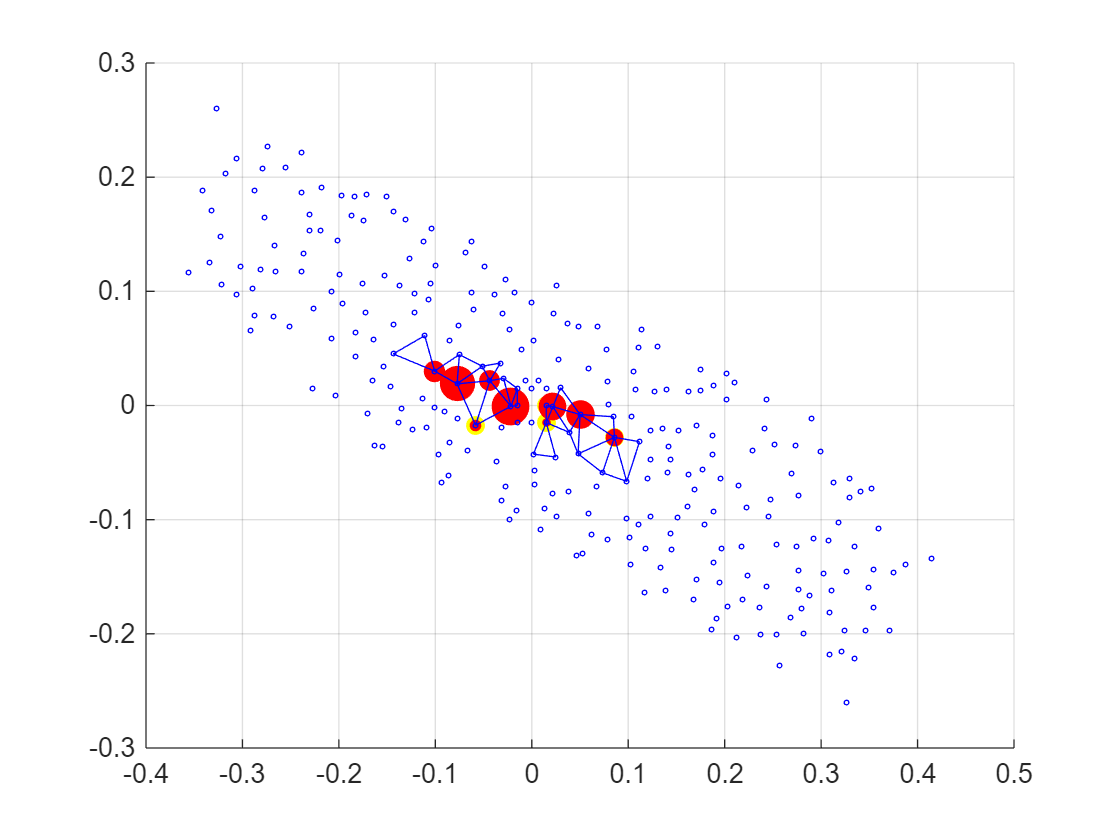

figure
if not(size(bad_ind_new3)==0)
    bad_points_new3 = zeros(2, length(bad_ind_new3(:,1)));
    bad_triangles_new3 = zeros(length(bad_ind_new3(:,1)), 3);
    for ml = 1:length(bad_ind_new3(:,1))
        bad_points_new3(:,ml) = [v_new3(1,C_new3(bad_ind_new3(ml,1),bad_ind_new3(ml,2))); v_new3(2,C_new3(bad_ind_new3(ml,1),bad_ind_new3(ml,2)))]; % points' coordinates
        bad_triangles_new3(ml,:) = C_new3(bad_ind_new3(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new3(1,:), bad_points_new3(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new3(1,:), bad_points_new3(2,:), bad_ind_new3(:,3).*200./max(bad_ind_new3(:,3)), 'r', 'filled')
    triplot(bad_triangles_new3, v_new3(1,:), v_new3(2,:))
end
scatter(v_new3(1,:), v_new3(2,:), 3, 'b')
grid on

[pointlist_new3,alpha_new3] = sublevelset(dX_new3,C_new3,v_new3,gs_new3,bs_new3,vals_new3,1,[.2 .6 1]);

pointlist_new3 =     0.3306   -0.0815
    0.3299   -0.0802
    0.3295   -0.0800
    0.3159   -0.0669
    0.3091   -0.0596
    0.2898   -0.0468
    0.2728   -0.0388
    0.2686   -0.0349
    0.2425   -0.0222
    0.2405   -0.0216


alpha_new3 = 187.0501

sublevelset(dX_new2,C_new2,v_new2,gs_new2,bs_new2,vals_new2,0,[.2 .2 .6]);

ans =    -0.4794    0.3359
   -0.4949    0.3328
   -0.5200    0.3247
   -0.5253    0.3200
   -0.5342    0.3111
   -0.5472    0.2777
   -0.5476    0.2770
   -0.5468    0.2756
   -0.5321    0.2365
   -0.5216    0.2241


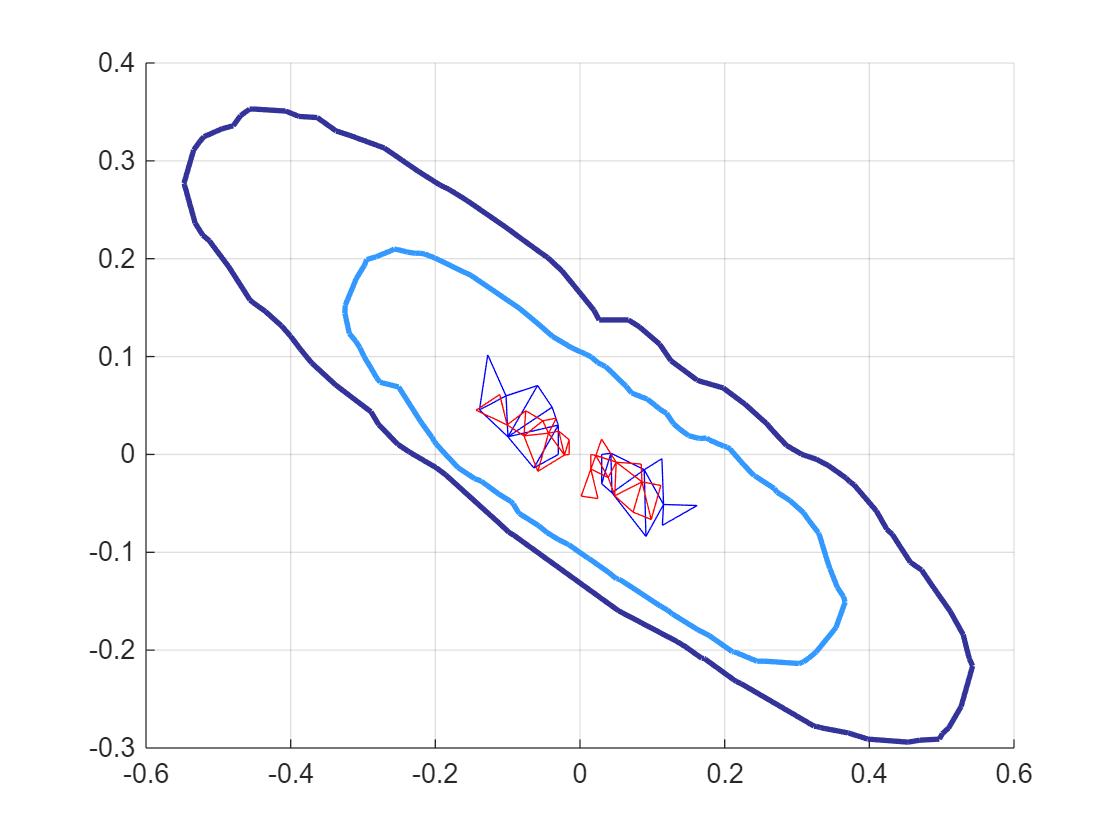

triplot(bad_triangles_new2, v_new2(1,:), v_new2(2,:))
triplot(bad_triangles_new3, v_new3(1,:), v_new3(2,:),'red')
grid on

creating new vertices... 


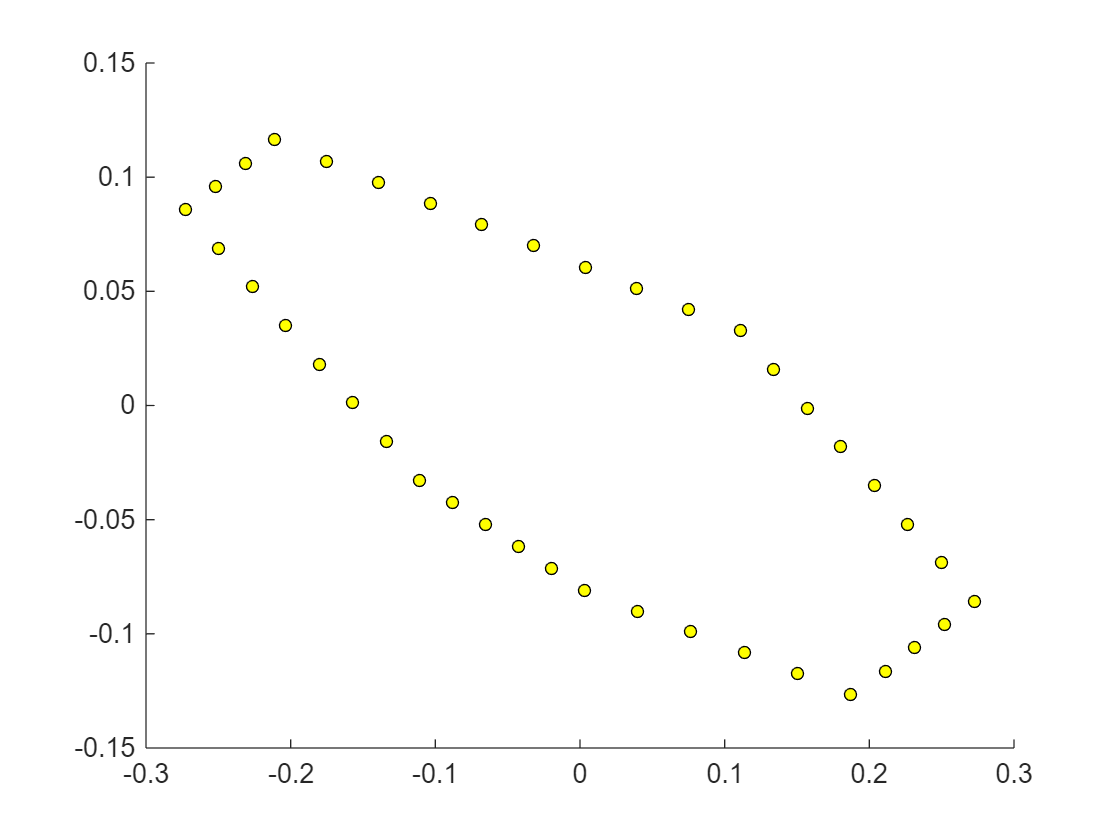

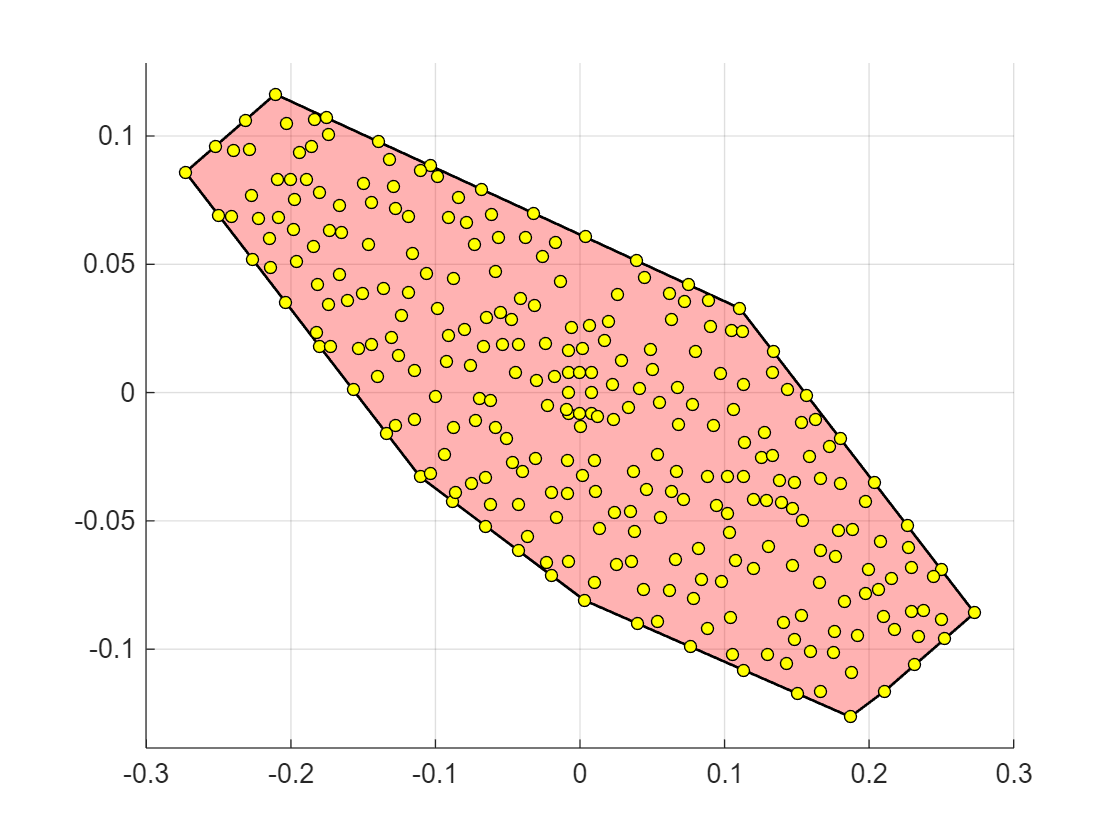

Elapsed time is 0.069386 seconds.
vertices created
 
Elapsed time is 0.072276 seconds.
polyhedra construction and plot ended
 
cleaning the tessellation...
Elapsed time is 1.361119 seconds.
tessellation cleaning ended
 


[v_new4,C_new4,Nv_new4,Nc_new4,dX_new4,Tess_new4,beta_new4] = TessellationFinderV3(270,v_new3,bad_triangles_new3,0.08*l_A,'random',pointlist_new3,0.013);

sublevelset(dX_new3,C_new3,v_new3,gs_new3,bs_new3,vals_new3,1,[.2 .6 1]);

ans =     0.3306   -0.0815
    0.3299   -0.0802
    0.3295   -0.0800
    0.3159   -0.0669
    0.3091   -0.0596
    0.2898   -0.0468
    0.2728   -0.0388
    0.2686   -0.0349
    0.2425   -0.0222
    0.2405   -0.0216


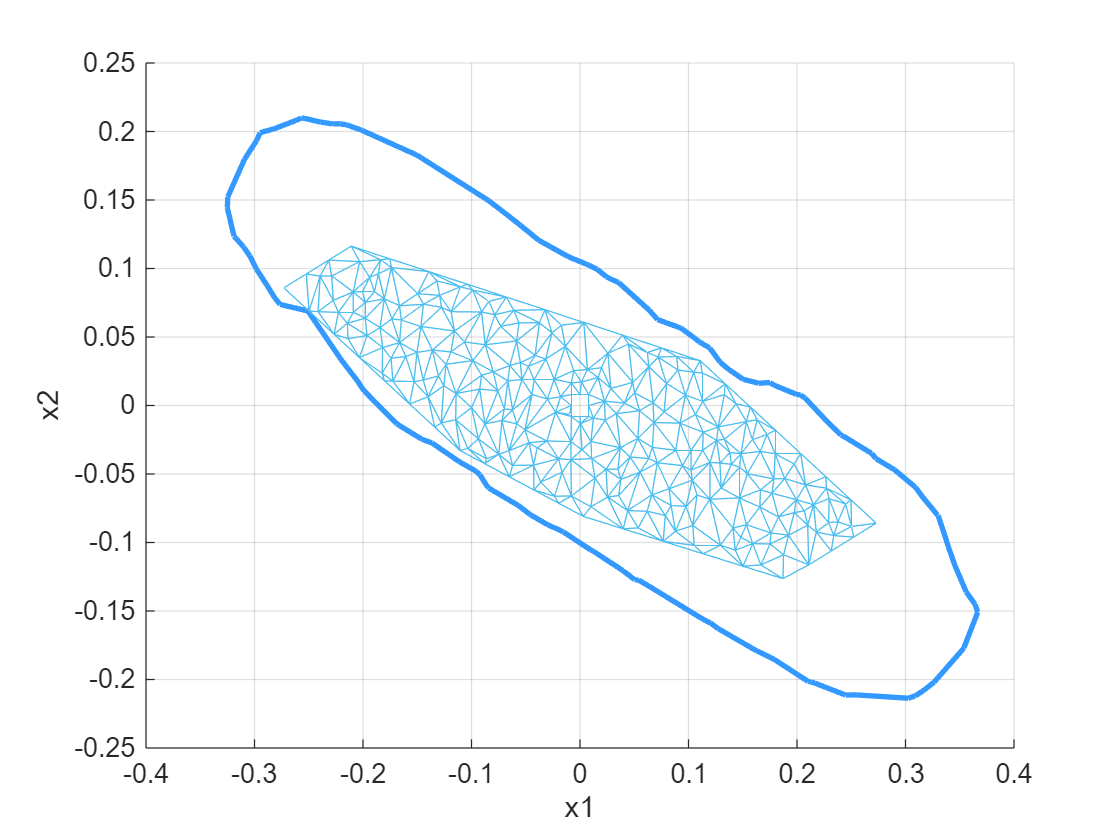

triplot(C_new4, v_new4(1,:), v_new4(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
xlabel('x1')
ylabel('x2')
grid on;

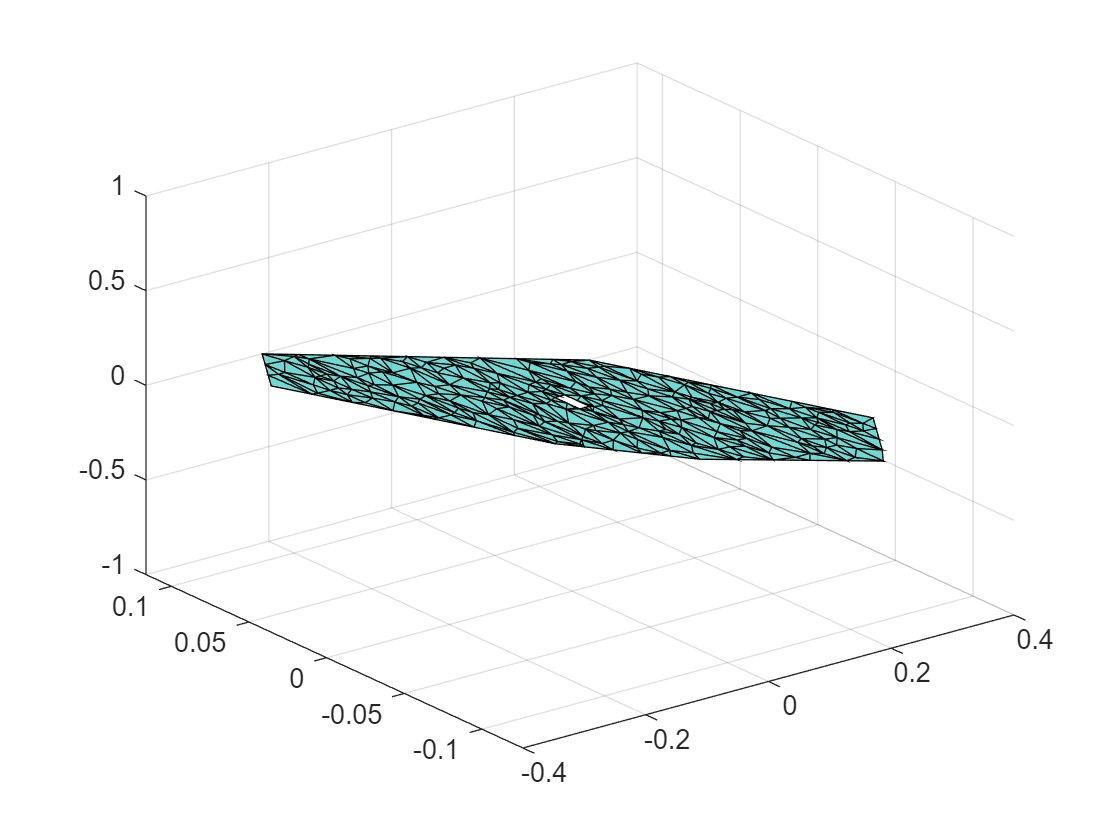

figure
trisurf(C_new4,v_new4(1,:),v_new4(2,:),zeros(length(v_new4),1),'FaceAlpha',.6)
grid on

l_new4 = [min(v_new4(1,:)),max(v_new4(1,:));min(v_new4(2,:)),max(v_new4(2,:))];
[x_new4,f_new4,Nd_new4] = DataGenerator(300,sample_ratio,l_new4,v_new4,Tess_new4,system,M,nrm,1);

Is data valid? => 1


We plot the resulting dataset. The purple circles are the datapoints and the orange arrows their image by the function.

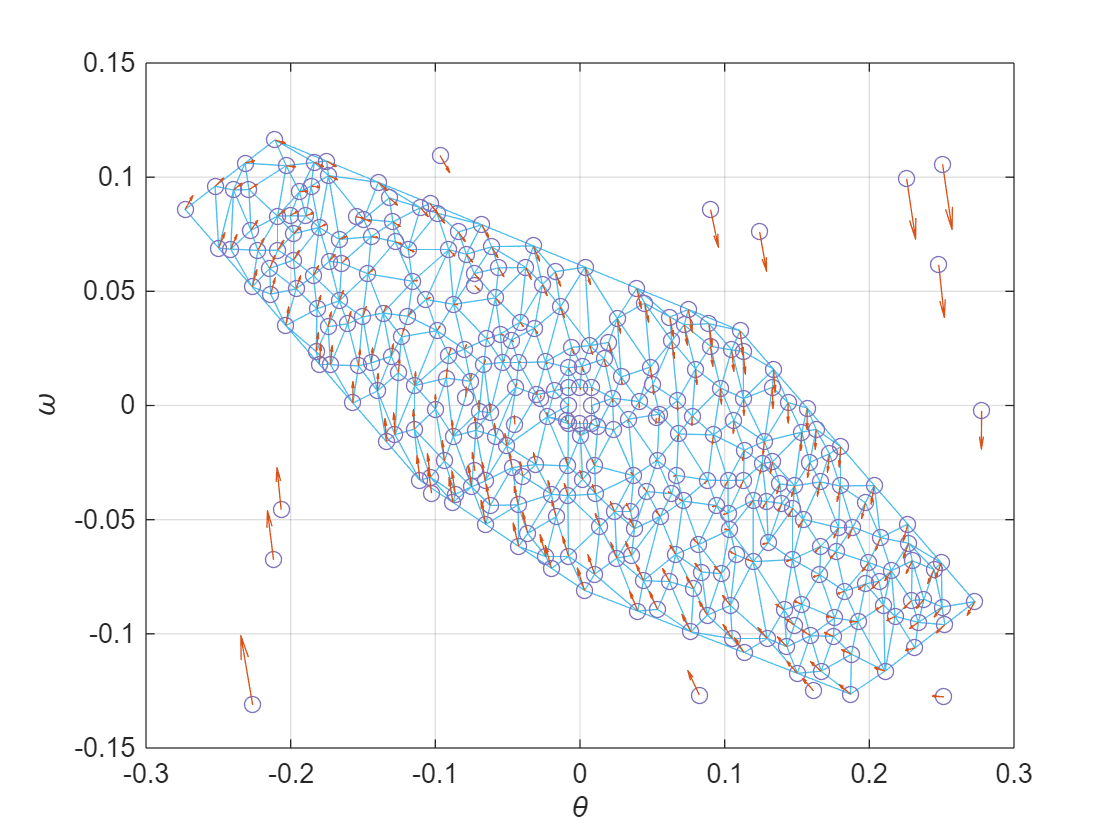

figure
triplot(C_new4, v_new4(1,:), v_new4(2,:), Color=[0.3010 0.7450 0.9330], LineWidth=0.2)
hold on
scatter(x_new4(1,:), x_new4(2,:), 'MarkerEdgeColor', [0.5 0.4470 0.7410])
quiver(x_new4(1,:), x_new4(2,:), f_new4(1,:), f_new4(2,:), Color=[0.8500 0.3250 0.0980])
grid on
xlabel('\theta')
ylabel('\omega')

clear gs_new4 bs_new4 vals_new4 ss_new4 sum_ss_new4
[gs_new4,bs_new4,vals_new4,ss_new4,sum_ss_new4] = OptimisationProblem(x_new4,f_new4,M,v_new4,C_new4,eps,eta,alpha,beta,dA,dX_new4,lim_mode,nrm,0,0,0);

 
starting constraint building...
total loops : 508
1 loops done
2 loops done
3 loops done
4 loops done
5 loops done
6 loops done
7 loops done
8 loops done
9 loops done
10 loops done
11 loops done
12 loops done
13 loops done
14 loops done
15 loops done
16 loops done
17 loops done
18 loops done
19 loops done
20 loops done
21 loops done
22 loops done
23 loops done
24 loops done
25 loops done
26 loops done
27 loops done
28 loops done
29 loops done
30 loops done
31 loops done
32 loops done
33 loops done
34 loops done
35 loops done
36 loops done
37 loops done
38 loops done
39 loops done
40 loops done
41 loops done
42 loops done
43 loops done
44 loops done
45 loops done
46 loops done
47 loops done
48 loops done
49 loops done
50 loops done
51 loops done
52 loops done
53 loops done
54 loops done
55 loops done
56 loops done
57 loops done
58 loops done
59 loops done
60 loops done
61 loops done
62 loops done
63 loops done
64 loops done
65 loops done
66 loops done
67 loops done
68 loops done
69 lo

ans = struct with fields:
    yalmipversion: '20230622'
    matlabversion: '24.2.0.2833386 (R2024b) Update 4'
       yalmiptime: 1.3219e+04
       solvertime: 100.6745
             info: 'Successfully solved (MOSEK-CONE)'
          problem: 0


Elapsed time is 13495.613808 seconds.
optimization ended
 


fprintf('Computed optimal value : %f\n', -eta*length(C_new4)*3)

Computed optimal value : -7620.000000


fprintf('Obtained optimal value : %f\n', sum_ss_new4)

Obtained optimal value : -7309.249608


fprintf('Error : %f\n', sum_ss_new4 + eta*length(C_new4)*3)

Error : 310.750392


We plot the solution in 3D, each triangle is plotted independently from the others.

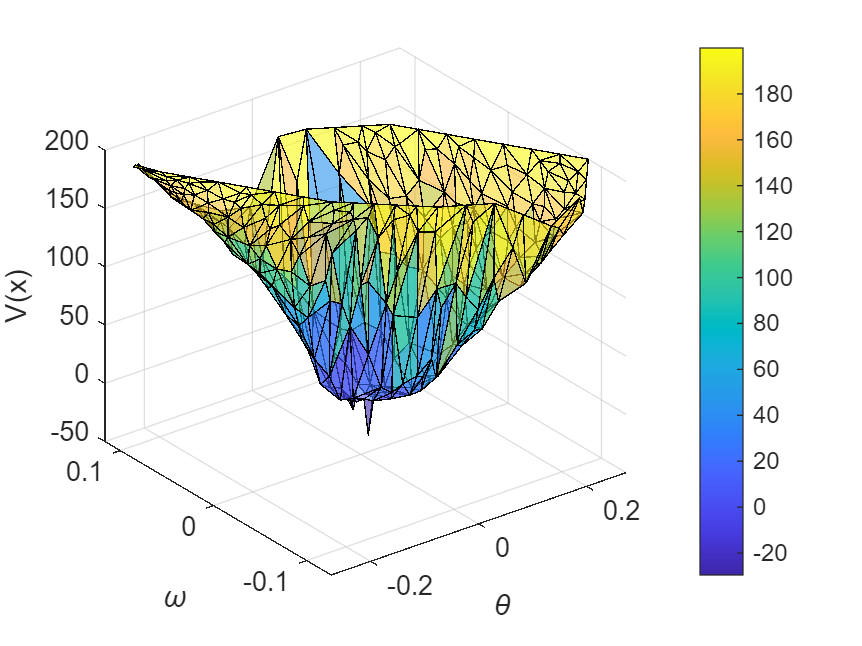

figure
trisurf(C_new4,v_new4(1,:),v_new4(2,:),vals_new4,'FaceAlpha',0.6)
xlabel('\theta')
ylabel('\omega')
zlabel('V(x)')
grid on
colorbar

clear bad_ind_new4 bad_triangles_new4 bad_points_new4
bad_ind_new4 = [];
for c = 1:length(ss_new4)
    for i = 1:3
        if ss_new4(i,c) >= 0
            bad_ind_new4 = [bad_ind_new4; [c, i, ss_new4(i,c)]];
        end
    end
end

Next, we plot the affected triangles and the points causing this mishap in red dots. The radius of the red dots is proportional to the positivity of the slack variable associated. All of the vertices are plotted in the background as small blue dots for reference, this means that if there are only those blue dots, there are no positive slack variables

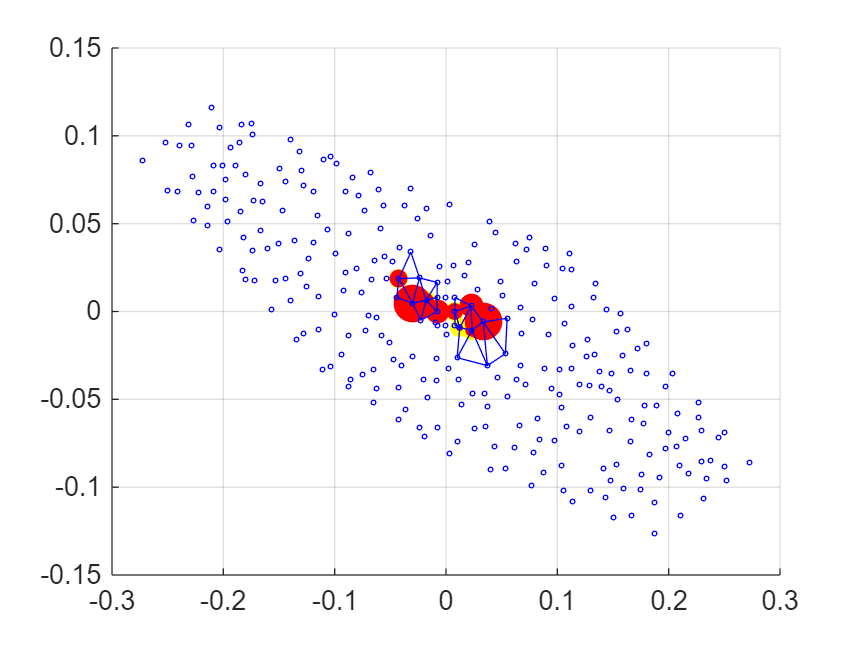

figure
if not(size(bad_ind_new4)==0)
    bad_points_new4 = zeros(2, length(bad_ind_new4(:,1)));
    bad_triangles_new4 = zeros(length(bad_ind_new4(:,1)), 3);
    for ml = 1:length(bad_ind_new4(:,1))
        bad_points_new4(:,ml) = [v_new4(1,C_new4(bad_ind_new4(ml,1),bad_ind_new4(ml,2))); v_new4(2,C_new4(bad_ind_new4(ml,1),bad_ind_new4(ml,2)))]; % points' coordinates
        bad_triangles_new4(ml,:) = C_new4(bad_ind_new4(ml,1),:); % triangles' indices
    end
    scatter(bad_points_new4(1,:), bad_points_new4(2,:), 50, 'yellow', 'filled')
    hold on
    scatter(bad_points_new4(1,:), bad_points_new4(2,:), bad_ind_new4(:,3).*200./max(bad_ind_new4(:,3)), 'r', 'filled')
    triplot(bad_triangles_new4, v_new4(1,:), v_new4(2,:))
end
scatter(v_new4(1,:), v_new4(2,:), 3, 'b')
grid on

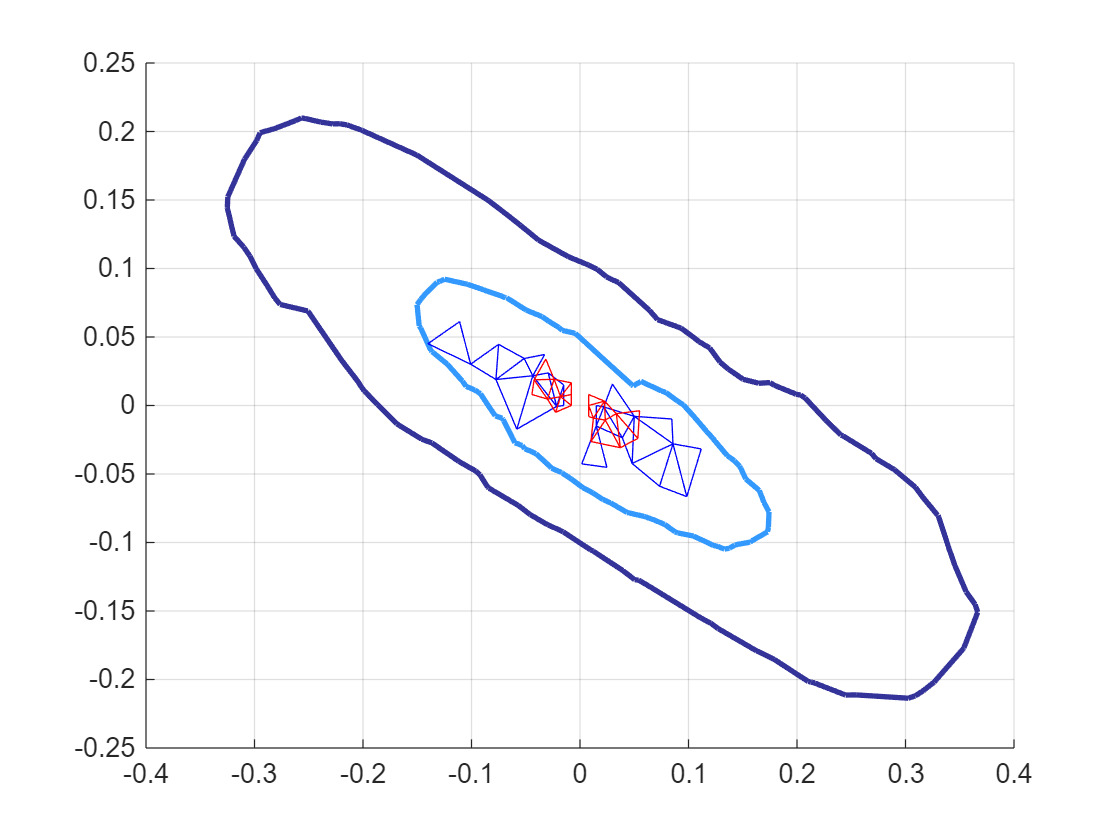

[pointlist_new4,alpha_new4] = sublevelset(dX_new4,C_new4,v_new4,gs_new4,bs_new4,vals_new4,1,[.2 .6 1]);
sublevelset(dX_new3,C_new3,v_new3,gs_new3,bs_new3,vals_new3,0,[.2 .2 .6]);
triplot(bad_triangles_new3, v_new3(1,:), v_new3(2,:))
triplot(bad_triangles_new4, v_new4(1,:), v_new4(2,:),'red')
grid on